# This exercise is to in-sample estimate volatility via different methods

We use the in-sample information for forecast.

# This exercise is to in-sample estimate volatility via different methods

We use the in-sample information for forrcast.

clc,clear
addpath("Functions/")
% % addpath("m_Files_ClusterPartition/")
% % addpath("m_Files_GARCHfamily/")
% % addpath("m_Files_Color/colormap/");
% 
% % load("dax_rv_11to22.mat")
% % load("ftse_rv_11to22.mat")
% % load("nikkie_rv_11to22.mat")
% % load("sp_rv_08to22.mat")
% dax=readtable("DAX_0608.xlsx");
% dax(:,3:4)=[];dax.Properties.VariableNames=["Date","Return"];
% % dax=sortrows(dax);
% ftse=readtable("FTSE_0608.xlsx");
% ftse(:,3:4)=[];dax.Properties.VariableNames=["Date","Return"];
% % ftse=sortrows(ftse);
% % nikkie=readtable("NIKKIE_daily.xlsx");
% % nikkie(:,2:4)=[];nikkie.Properties.VariableNames=["Date","Price"];
% % nikkie=sortrows(nikkie);
% sp=readtable("S&P500_0608.xlsx");
% sp(:,3:4)=[];dax.Properties.VariableNames=["Date","Return"];
% % sp=sortrows(sp);
% 
% target_year=2022;
% 
% logret=[0;price2ret(sp.Price)];

## S&P 500

datatable=readtable("SP500_0608.xlsx");
results_folder='Results_SP';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);
% symmetric HAR
lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -2.7768     0.57683     -4.814     1.801e-06
    x1              0.43463    0.042377     10.256    3.8427e-23
    x2              0.28736    0.064446      4.459    9.5396e-06
    x3             0.019568    0.068321    0.28641       0.77465


Number of observations: 730, Error degrees of freedom: 726
Root Mean Squared Error: 0.611
R-squared: 0.383,  Adjusted R-Squared: 0.381
F-statistic vs. constant model: 151, p-value = 7.63e-76

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 1.3614e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 2.3016e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 1.3342e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 2.2231e-05


% asymmetric HAR
lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   ___________    ________    _________    __________

    (Intercept)        -2.8167      0.5649      -4.9862    7.7149e-07
    x1                 0.33075    0.047544       6.9567    7.8135e-12
    x2                 0.36128    0.066815       5.4072    8.7075e-08
    x3                 0.05447    0.067055      0.81232       0.41687
    x4                  77.185      71.704       1.0764       0.28209
    x5             -0.00049536    0.026866    -0.018438       0.98529
    x6                 0.21824    0.038398       5.6837    1.9123e-08


Number of observa

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 1.3136e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 2.2619e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 1.2746e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 2.1790e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    false     0.03     4.77     6.63 
    true      0.03     4.77     3.84 
    true      0.03     4.77     2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    7.4942e-06     1.1473e-06        6.5318      6.5002e-11
    GARCH{1}       0.71007       0.055852        12.713      4.9845e-37
    ARCH{1}        0.16354       0.042367          3.86       0.0001134
    Offset      0.00080068     0.00025091        3.1911       0.0014175



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
% if K==numel(v_GARCH)
%     K=K-1;
% end
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

EGARCH

% Mdl=egarch('GARCH',NaN,'ARCH',NaN,'Offset',NaN,'Leverage',NaN);
% EstMdl = estimate(Mdl,ret);
% v_EGARCH = infer(EstMdl,ret);
% [LB,J,~]=Fisher_div_sqr(v_EGARCH,100);
% K = OptimalClusterNumber(v_EGARCH,LB);
% % if K==numel(v_EGARCH)
% %     K=K-1;
% % end
% [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
% v_CPEGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPEGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant        5.147e-06     1.7398e-06          2.9584     0.0030929
    GARCH{1}          0.75823       0.040017          18.948    4.6304e-80
    ARCH{1}             2e-12       0.030682      6.5185e-11             1
    Leverage{1}       0.32877       0.063154          5.2058    1.9311e-07
    Offset         0.00045187     0.00025154          1.7964      0.072434



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
% if K==numel(v_GJRGARCH)
%     K=K-1;
% end
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation, probabilities, ~] = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0000    0.1888    0.7460
    0.0000    0.2365    0.6641


estimation.transM

ans =     0.1468    0.4842
    0.8532    0.5158


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
% if K==numel(v_RSGARCH)
%     K=K-1;
% end
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 3.7165e-05

mean(abs(v_CPRSGARCH-rv))

ans = 3.8656e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 3.3363e-05

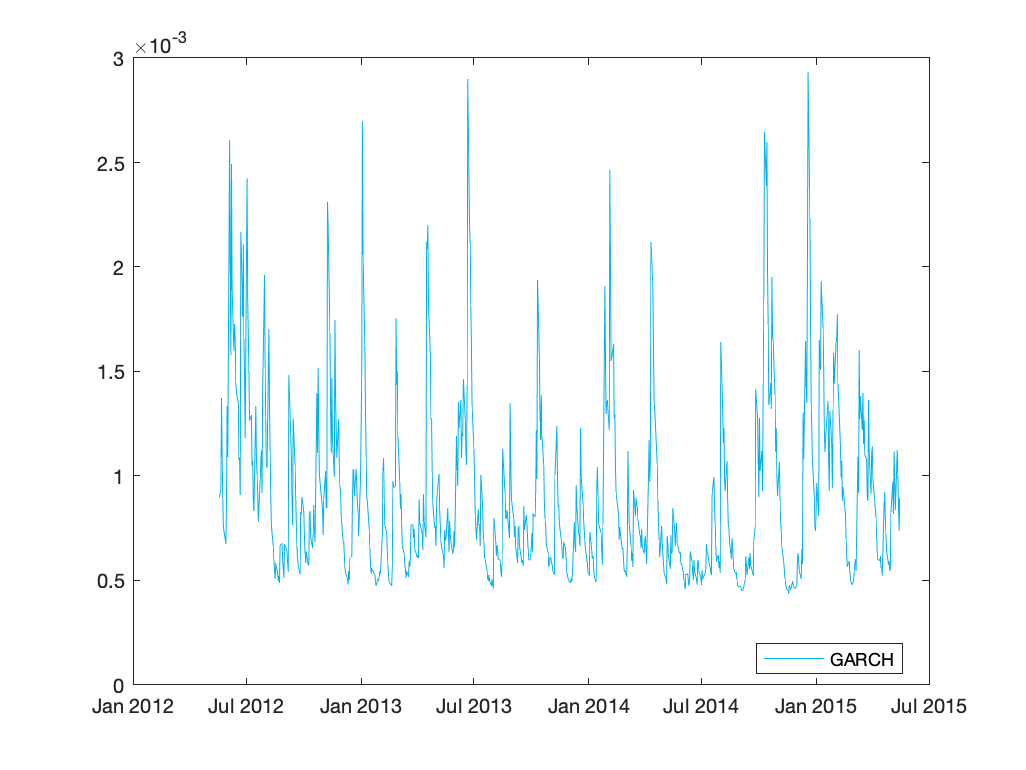

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");

Timeline_insample=datatable.Date(index);

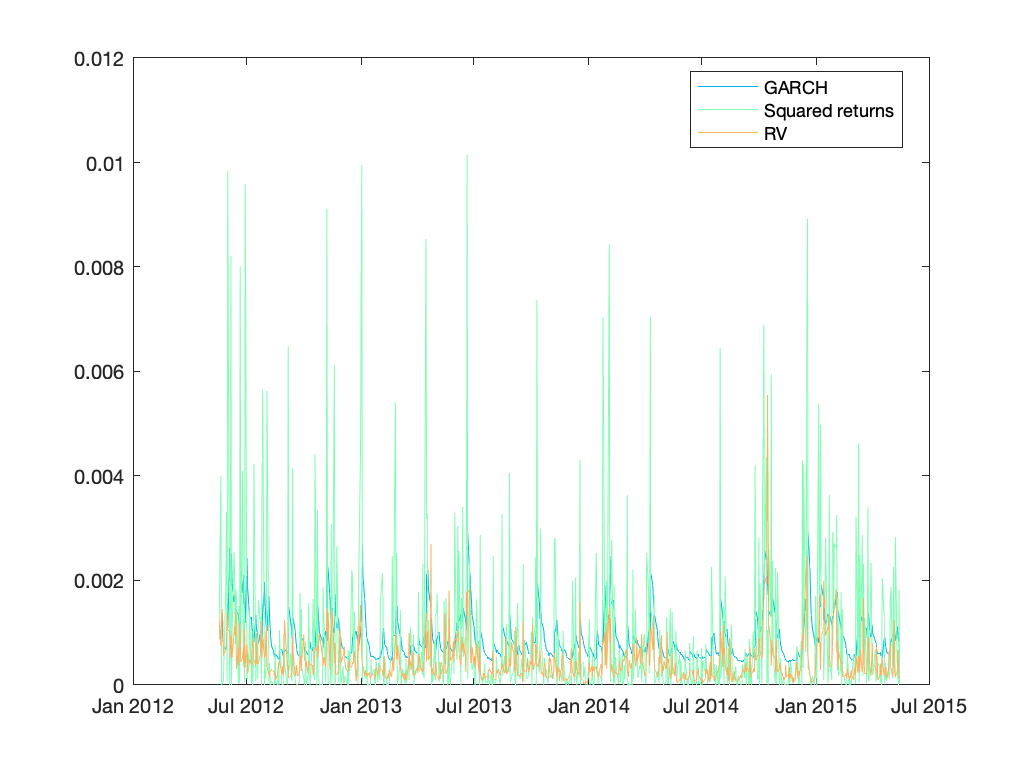

figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(3,:))
legend("GARCH","Squared returns","RV","Location","best");

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
subplot(2,2,1)
plot(Timeline_insample,v_GARCH, "Color",col(1,:))
legend("GARCH","Location","best");
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 6.2278e-04

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 5.0308e-04

subplot(2,2,2)
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
legend("GJR","Location","best");
mse(v_GJRGARCH,rv).^(1/2)*sqrt(250)

ans = 7.5989e-04

mean(abs(v_GJRGARCH-rv))*sqrt(250)

ans = 5.3950e-04

subplot(2,2,3)
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
legend("RSGARCH","Location","best");
mse(v_RSGARCH,rv).^(1/2)*sqrt(250)

ans = 7.4502e-04

mean(abs(v_RSGARCH-rv))*sqrt(250)

ans = 5.8763e-04

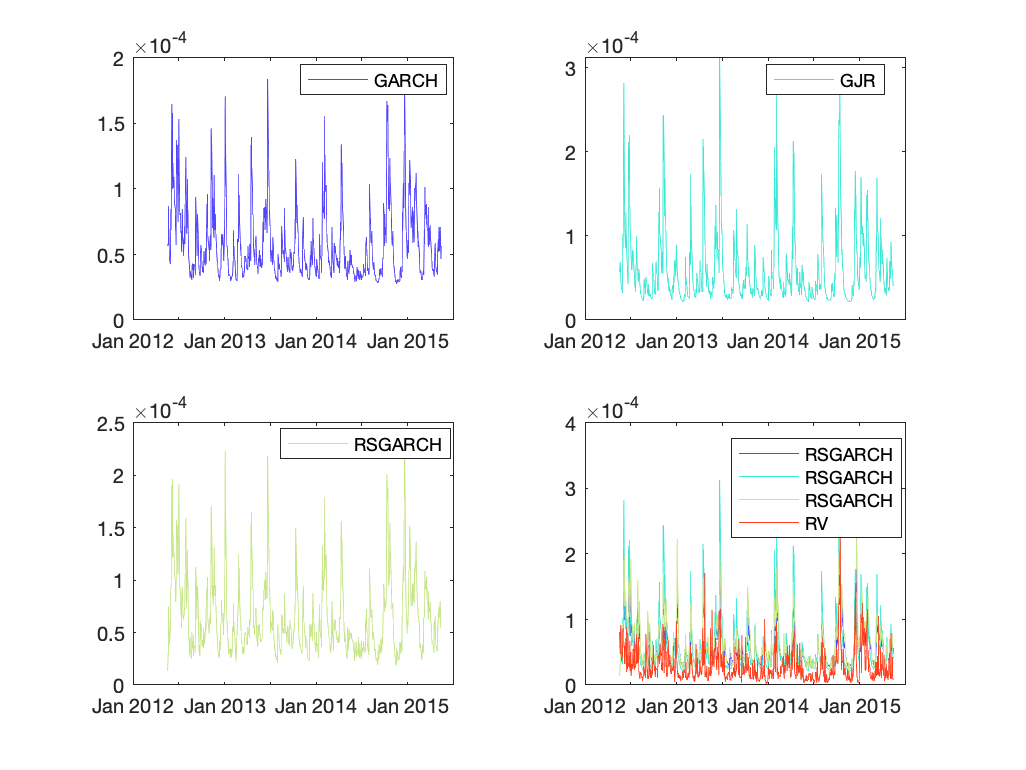

subplot(2,2,4)
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
plot(Timeline_insample,rv, "Color",col(10,:));
legend("RSGARCH","RSGARCH","RSGARCH","RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_GARCH_GJR_RSGARCH.png'])

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 6.2278e-04

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 5.0308e-04

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
% K = OptimalClusterNumber(v_GARCH,LB);
K = 2;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH1,rv).^(1/2)*sqrt(250)

ans = 6.1554e-04

mean(abs(v_CPGARCH1-rv))*sqrt(250)

ans = 5.4225e-04

K = 3;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH2,rv).^(1/2)*sqrt(250)

ans = 6.0714e-04

mean(abs(v_CPGARCH2-rv))*sqrt(250)

ans = 5.3404e-04

K = 4;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH3,rv).^(1/2)*sqrt(250)

ans = 6.0775e-04

mean(abs(v_CPGARCH3-rv))*sqrt(250)

ans = 5.3442e-04

K = 5;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH4,rv).^(1/2)*sqrt(250)

ans = 6.0654e-04

mean(abs(v_CPGARCH4-rv))*sqrt(250)

ans = 5.3271e-04

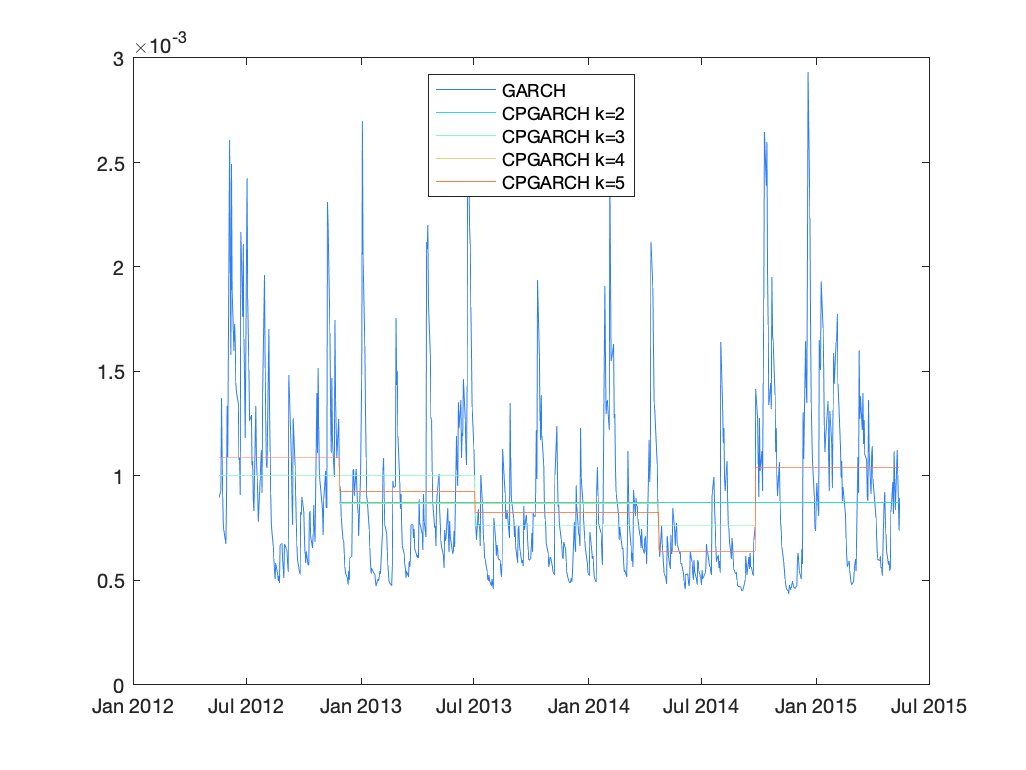

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","Location","best");

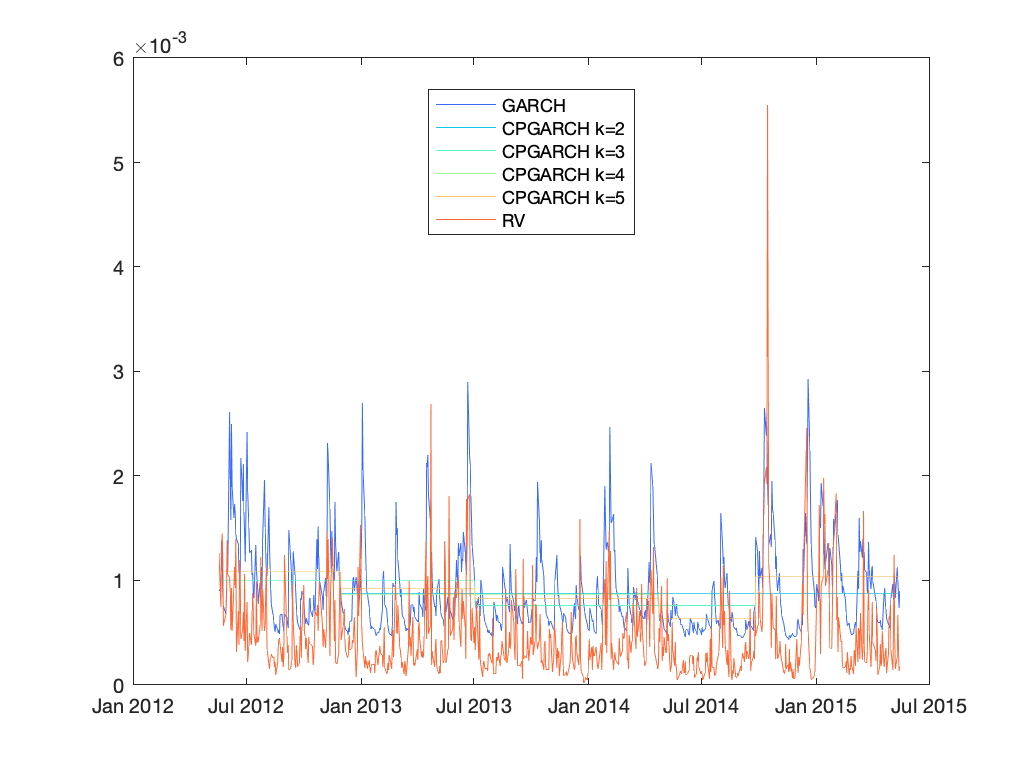

figure;
col=rainbow(6);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(6,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","RV","Location","best");

% RMSE=zeros(size(2:300));
% MAE=zeros(size(2:300));
% K_h=zeros(size(2:300));
% for h=2:300
%     h
%     [LB,J,~]=Fisher_div_sqr(v_GARCH,h);
%     K = OptimalClusterNumber(v_GARCH,LB);
%     v_CPGARCH=Vol_ClusterPartition(v_GARCH,K,J);
%     K_h(h-1)=K;
%     RMSE(h-1)=mse(v_CPGARCH,rv).^(1/2)*sqrt(250);
%     MAE(h-1)=mean(abs(v_CPGARCH-rv))*sqrt(250);
% end

h = 2

h = 3

h = 4

h = 5

h = 6

h = 7

h = 8

h = 9

h = 10

h = 11

h = 12

h = 13

h = 14

h = 15

h = 16

h = 17

h = 18

h = 19

h = 20

h = 21

h = 22

h = 23

h = 24

h = 25

h = 26

h = 27

h = 28

h = 29

h = 30

h = 31

h = 32

h = 33

h = 34

h = 35

h = 36

h = 37

h = 38

h = 39

h = 40

h = 41

h = 42

h = 43

h = 44

h = 45

h = 46

h = 47

h = 48

h = 49

h = 50

h = 51

h = 52

h = 53

h = 54

h = 55

h = 56

h = 57

h = 58

h = 59

h = 60

h = 61

h = 62

h = 63

h = 64

h = 65

h = 66

h = 67

h = 68

h = 69

h = 70

h = 71

h = 72

h = 73

h = 74

h = 75

h = 76

h = 77

h = 78

h = 79

h = 80

h = 81

h = 82

h = 83

h = 84

h = 85

h = 86

h = 87

h = 88

h = 89

h = 90

h = 91

h = 92

h = 93

h = 94

h = 95

h = 96

h = 97

h = 98

h = 99

h = 100

h = 101

h = 102

h = 103

h = 104

h = 105

h = 106

h = 107

h = 108

h = 109

h = 110

h = 111

h = 112

h = 113

h = 114

h = 115

h = 116

h = 117

h = 118

h = 119

h = 120

h = 121

h = 122

h = 123

h = 124

h = 125

h = 126

h = 127

h = 128

h = 129

h = 130

h = 131

h = 132

h = 133

h = 134

h = 135

h = 136

h = 137

h = 138

h = 139

h = 140

h = 141

h = 142

h = 143

h = 144

h = 145

h = 146

h = 147

h = 148

h = 149

h = 150

h = 151

h = 152

h = 153

h = 154

h = 155

h = 156

h = 157

h = 158

h = 159

h = 160

h = 161

h = 162

h = 163

h = 164

h = 165

h = 166

h = 167

h = 168

h = 169

h = 170

h = 171

h = 172

h = 173

h = 174

h = 175

h = 176

h = 177

h = 178

h = 179

h = 180

h = 181

h = 182

h = 183

h = 184

h = 185

h = 186

h = 187

h = 188

h = 189

h = 190

h = 191

h = 192

h = 193

h = 194

h = 195

h = 196

h = 197

h = 198

h = 199

h = 200

h = 201

h = 202

h = 203

h = 204

h = 205

h = 206

h = 207

h = 208

h = 209

h = 210

h = 211

h = 212

h = 213

h = 214

h = 215

h = 216

h = 217

h = 218

h = 219

h = 220

h = 221

h = 222

h = 223

h = 224

h = 225

h = 226

h = 227

h = 228

h = 229

h = 230

h = 231

h = 232

h = 233

h = 234

h = 235

h = 236

h = 237

h = 238

h = 239

h = 240

h = 241

h = 242

h = 243

h = 244

h = 245

h = 246

h = 247

h = 248

h = 249

h = 250

h = 251

h = 252

h = 253

h = 254

h = 255

h = 256

h = 257

h = 258

h = 259

h = 260

h = 261

h = 262

h = 263

h = 264

h = 265

h = 266

h = 267

h = 268

h = 269

h = 270

h = 271

h = 272

h = 273

h = 274

h = 275

h = 276

h = 277

h = 278

h = 279

h = 280

h = 281

h = 282

h = 283

h = 284

h = 285

h = 286

h = 287

h = 288

h = 289

h = 290

h = 291

h = 292

h = 293

h = 294

h = 295

h = 296

h = 297

h = 298

h = 299

h = 300

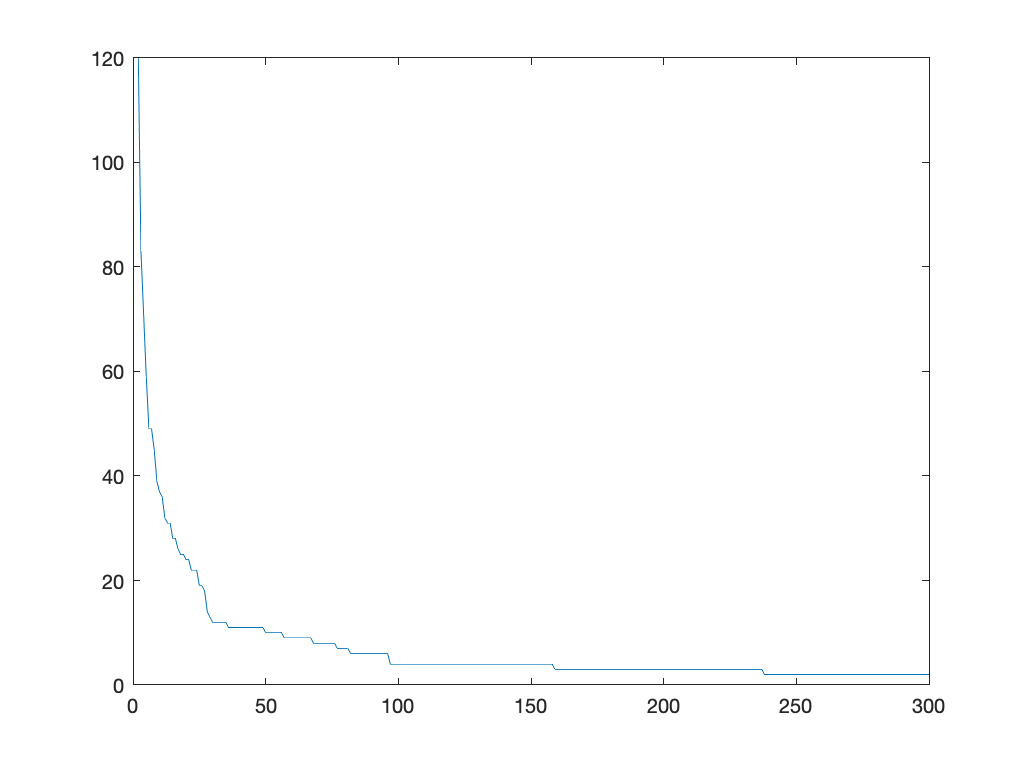

% figure;
% plot(2:300,K_h)

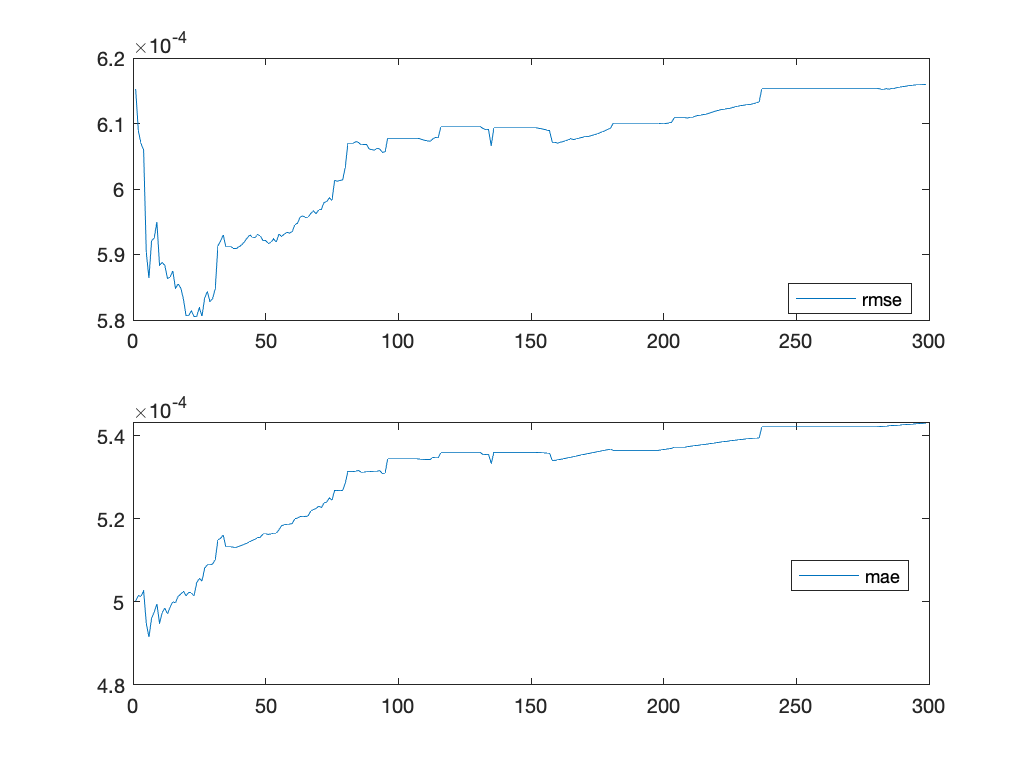

% figure;
% subplot(2,1,1);
% plot(RMSE);
% legend("rmse","Location","best");
% subplot(2,1,2);
% plot(MAE);
% legend("mae","Location","best");

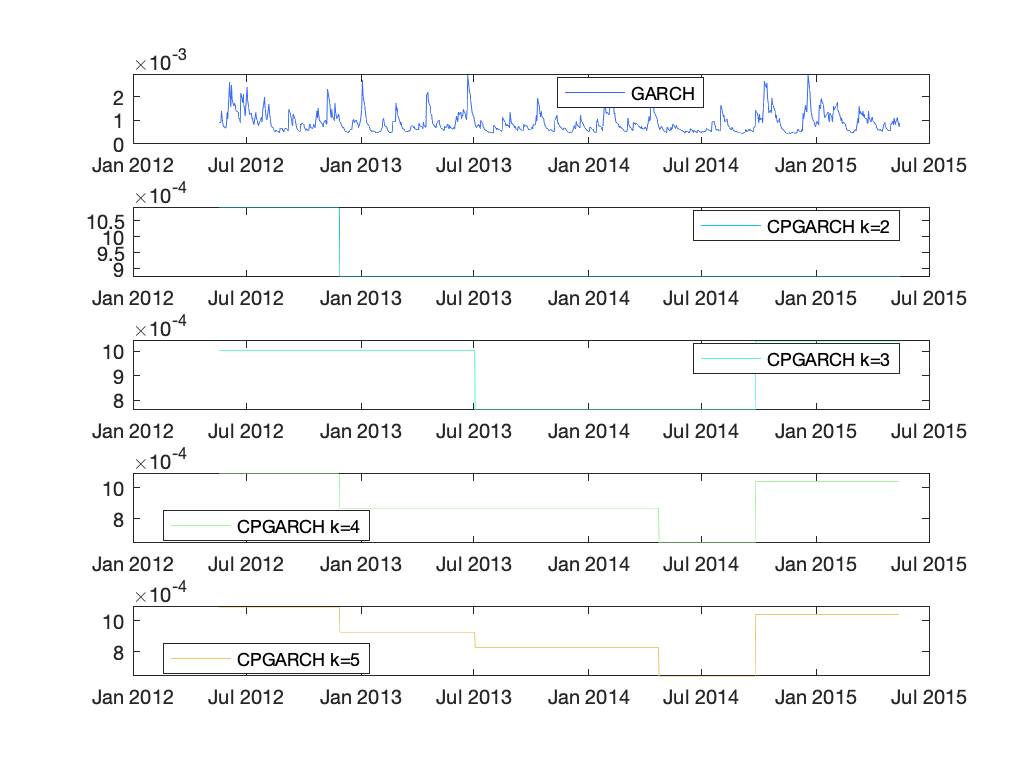

figure;
subplot(5,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");
subplot(5,1,2);
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
legend("CPGARCH k=2","Location","best");
subplot(5,1,3);
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
legend("CPGARCH k=3","Location","best");
subplot(5,1,4);
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
legend("CPGARCH k=4","Location","best");
subplot(5,1,5);
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("CPGARCH k=5","Location","best");

ret=datatable.Return(index);
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,10);
K = OptimalClusterNumber(v_GARCH,LB)

K = 37

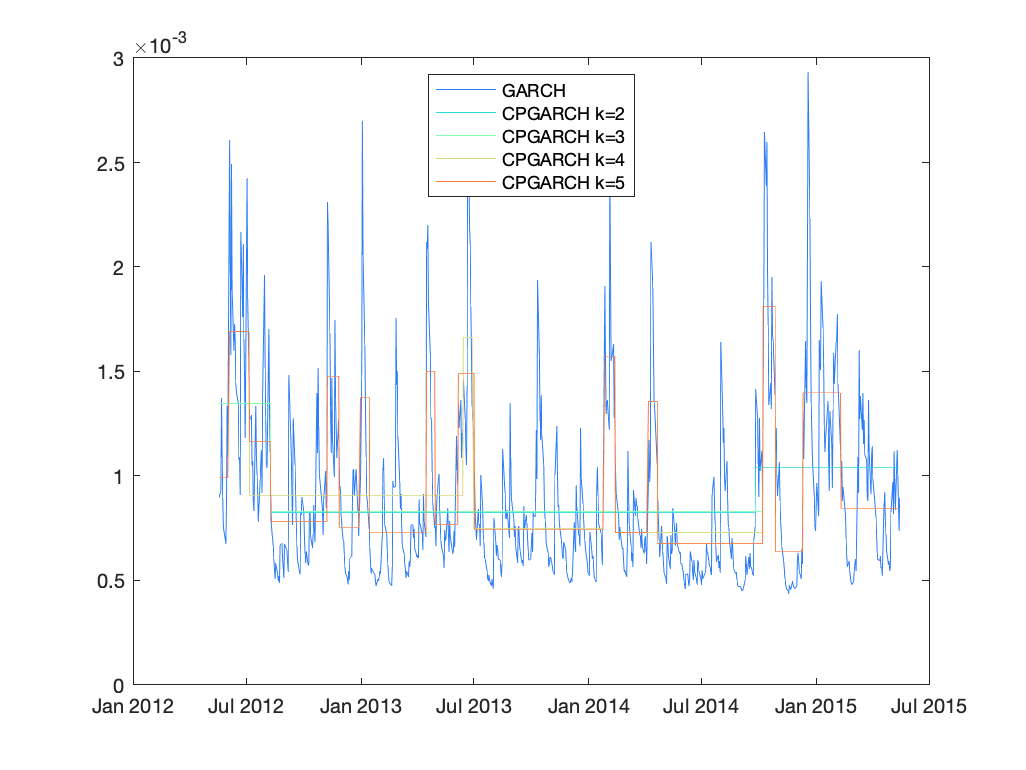

K = 3;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 6;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 11;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 20;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=3","CPGARCH k=6","CPGARCH k=11","CPGARCH k=20","Location","best");

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 4

[v_CPGARCH,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   133
   485
   593


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K2 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K2 = 3

[v_CPsr,Nodes2]=Vol_ClusterPartition(datatable.Return(index).^2,K2,J);
Nodes2

Nodes2 =      1
   278
   591


[LB,J,~]=Fisher_div_sqr(rv,100);
K3 = OptimalClusterNumber(rv,LB)

K3 = 3

[v_CPrv,Nodes3]=Vol_ClusterPartition(rv,K3,J);
Nodes3

Nodes3 =      1
   284
   592


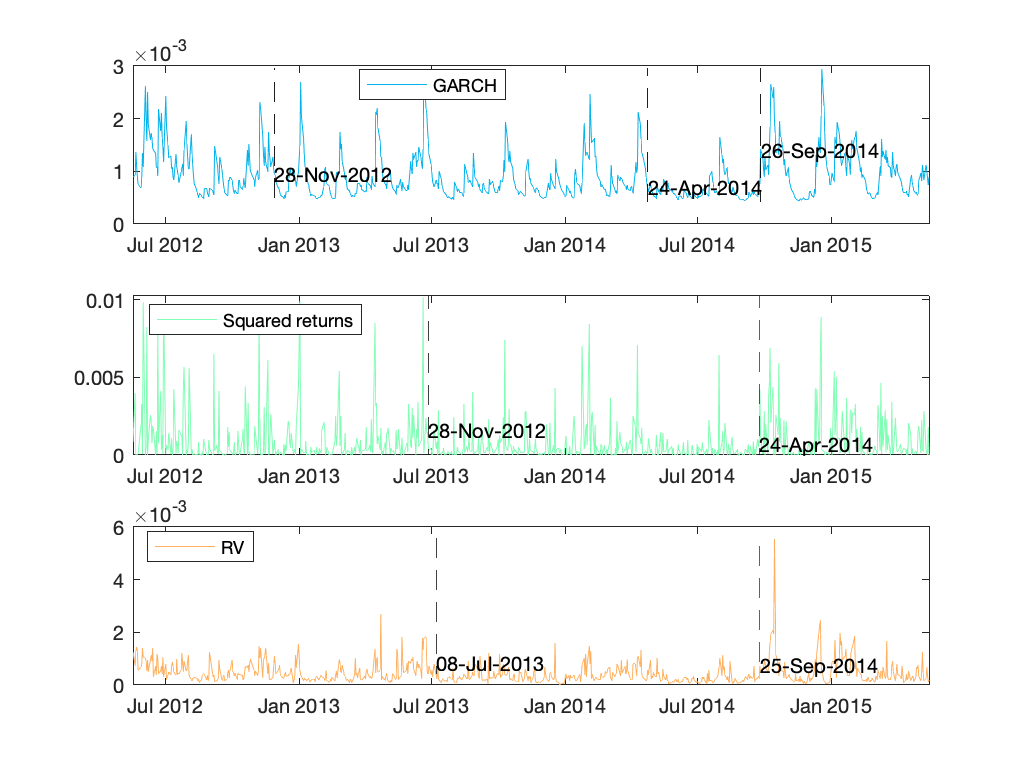

figure;
col=rainbow(3);
subplot(3,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes1)
plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes1(i)),v_GARCH(Nodes1(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
% plot([Timeline_insample(Nodes1(3)),Timeline_insample(Nodes1(3))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
% text(Timeline_insample(Nodes1(3)),v_GARCH(Nodes1(2))*sqrt(250),datestr(Timeline_insample(Nodes1(3))))
legend("GARCH","Location","best");
subplot(3,1,2);
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250), "Color",col(2,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes2)
plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[min(datatable.Return(index).^2*sqrt(250))*0.99,max(datatable.Return(index).^2*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes2(i)),v_GARCH(Nodes2(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
legend("Squared returns","Location","northwest");
subplot(3,1,3);
plot(Timeline_insample,rv*sqrt(250), "Color",col(3,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes3)
plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[min(v_GARCH*sqrt(250))*0.99,max(rv*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes3(i)),v_GARCH(Nodes3(i))*sqrt(250),datestr(Timeline_insample(Nodes3(i))))
end
legend("RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_CP.png'])

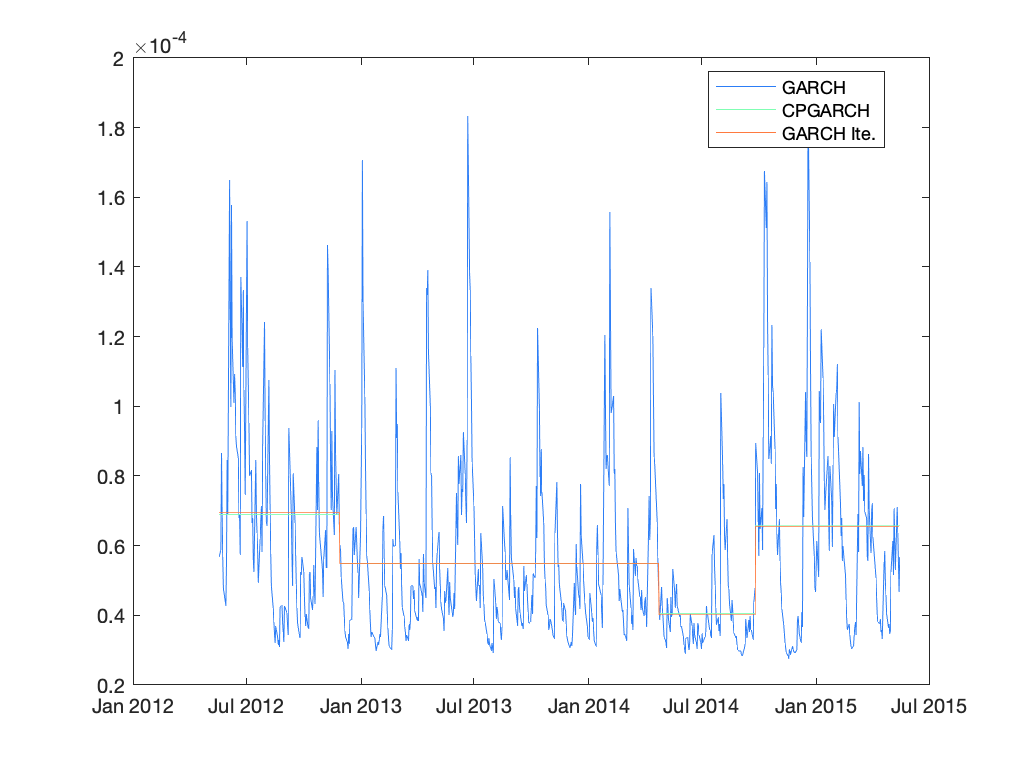

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH, "Color",col(3,:))
plot(Timeline_insample,v_CPGARCHiteration, "Color",col(5,:))
legend("GARCH","CPGARCH","GARCH Ite.","Location","best");

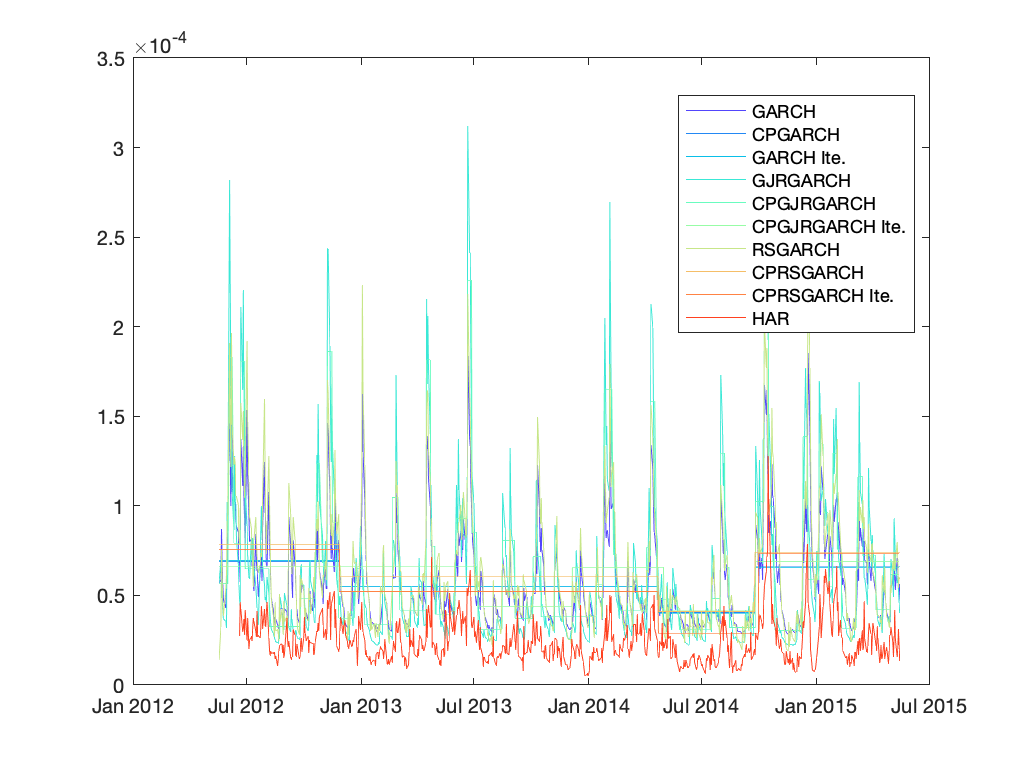

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(7,:));
plot(Timeline_insample,v_CPRSGARCH*sqrt(250), "Color",col(8,:))
plot(Timeline_insample,v_CPRSGARCHiteration*sqrt(250), "Color",col(9,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(10,:))
%plot(Time_insample,v_RSGARCH, "Color",col(10,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","Location","best");

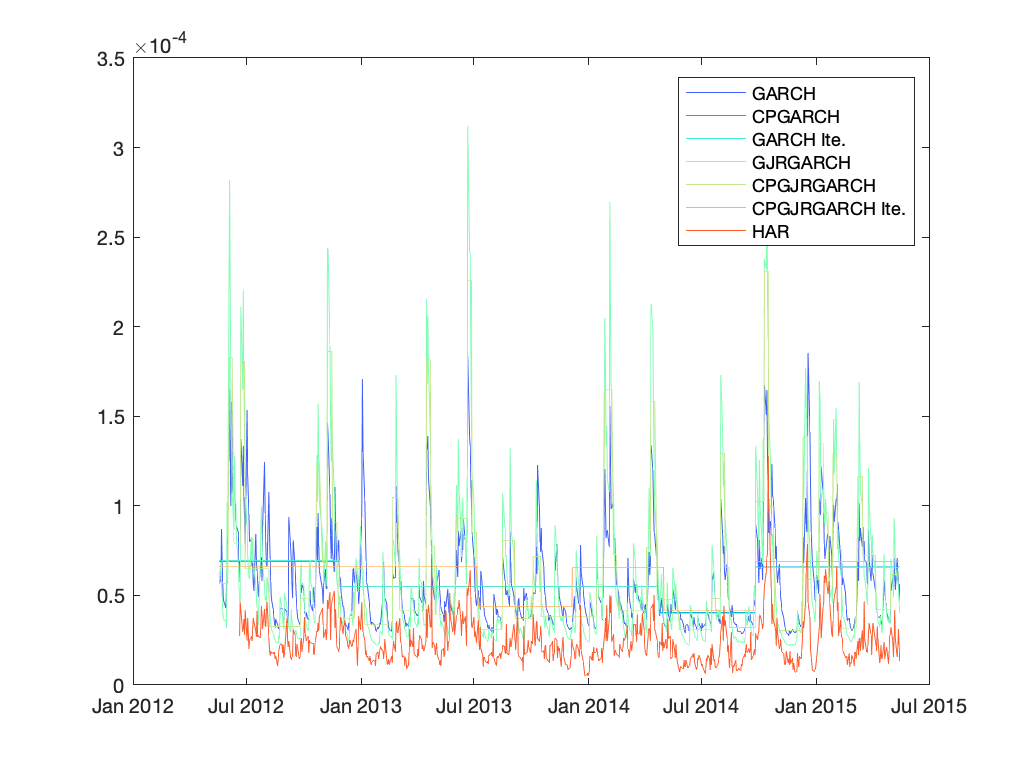

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(7);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(7,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH","CPGJRGARCH","CPGJRGARCH Ite.","HAR","Location","best");

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.50308    0.62278
    CPGARCH            0.53442    0.60775
    GARCH Ite.         0.53317    0.60685
    GJRGARCH            0.5395    0.75989
    CPGJRGARCH         0.53776    0.72676
    CPGJRGARCH Ite.    0.56218    0.63844
    RSGARCH            0.58763    0.74502
    CPRSGARCH           0.6112    0.68433
    CPRSGARCH Ite.     0.52752    0.61771
    HAR                0.21526    0.36392
    HAR_a              0.20769    0.35763
    CPHAR              0.21096     0.3515
    CPHAR_a            0.20154    0.34453


## DAX 30

datatable=readtable("DAX_0608.xlsx");
results_folder='Results_DAX';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);
% symmetric HAR
lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -1.7246     0.45225    -3.8135    0.00014862
    x1              0.23894    0.043269     5.5222    4.6568e-08
    x2              0.52277    0.070447     7.4208    3.2442e-13
    x3             0.061562    0.068941    0.89297       0.37217


Number of observations: 734, Error degrees of freedom: 730
Root Mean Squared Error: 0.551
R-squared: 0.403,  Adjusted R-Squared: 0.4
F-statistic vs. constant model: 164, p-value = 3e-81

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 3.1339e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 5.3054e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 3.0582e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 5.1750e-05


% asymmetric HAR
lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      -1.6781     0.44051    -3.8094    0.00015107
    x1               0.13061    0.045019     2.9012       0.00383
    x2                0.6168    0.070069     8.8027    9.6647e-18
    x3              0.084835    0.067175     1.2629       0.20703
    x4                723.95      672.53     1.0765       0.28208
    x5             -0.062686    0.026685    -2.3491      0.019086
    x6               0.24146    0.036108     6.6872     4.537e-11


Number of observations: 734, Error degrees of freedom

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 3.0383e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 5.1546e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 2.9105e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 4.9573e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    false     0.03     4.9      6.63 
    true      0.03     4.9      3.84 
    true      0.03     4.9      2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    5.0715e-06     2.9418e-06        1.7239          0.08472
    GARCH{1}       0.87052       0.036672        23.738      1.4486e-124
    ARCH{1}        0.08897       0.022081        4.0292       5.5974e-05
    Offset      0.00099499     0.00035529        2.8005         0.005102



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
% if K==numel(v_GARCH)
%     K=K-1;
% end
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

EGARCH

% Mdl=egarch('GARCH',NaN,'ARCH',NaN,'Offset',NaN,'Leverage',NaN);
% EstMdl = estimate(Mdl,ret);
% v_EGARCH = infer(EstMdl,ret);
% [LB,J,~]=Fisher_div_sqr(v_EGARCH,100);
% K = OptimalClusterNumber(v_EGARCH,LB);
% % if K==numel(v_EGARCH)
% %     K=K-1;
% % end
% [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
% v_CPEGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPEGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant       6.4446e-06     3.5412e-07          18.199    5.2708e-74
    GARCH{1}          0.85267       0.021318          39.997             0
    ARCH{1}             2e-12       0.019759      1.0122e-10             1
    Leverage{1}       0.18462       0.040985          4.5044    6.6547e-06
    Offset         0.00062469     0.00036187          1.7263      0.084298



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
% if K==numel(v_GJRGARCH)
%     K=K-1;
% end
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation, probabilities, ~] = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0001    0.1344    0.4393
    0.0000    0.0857    0.8597


estimation.transM

ans =     0.7126    0.1955
    0.2874    0.8045


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
% if K==numel(v_RSGARCH)
%     K=K-1;
% end
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 5.5500e-05

mean(abs(v_CPRSGARCH-rv))

ans = 5.8093e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 5.6737e-05

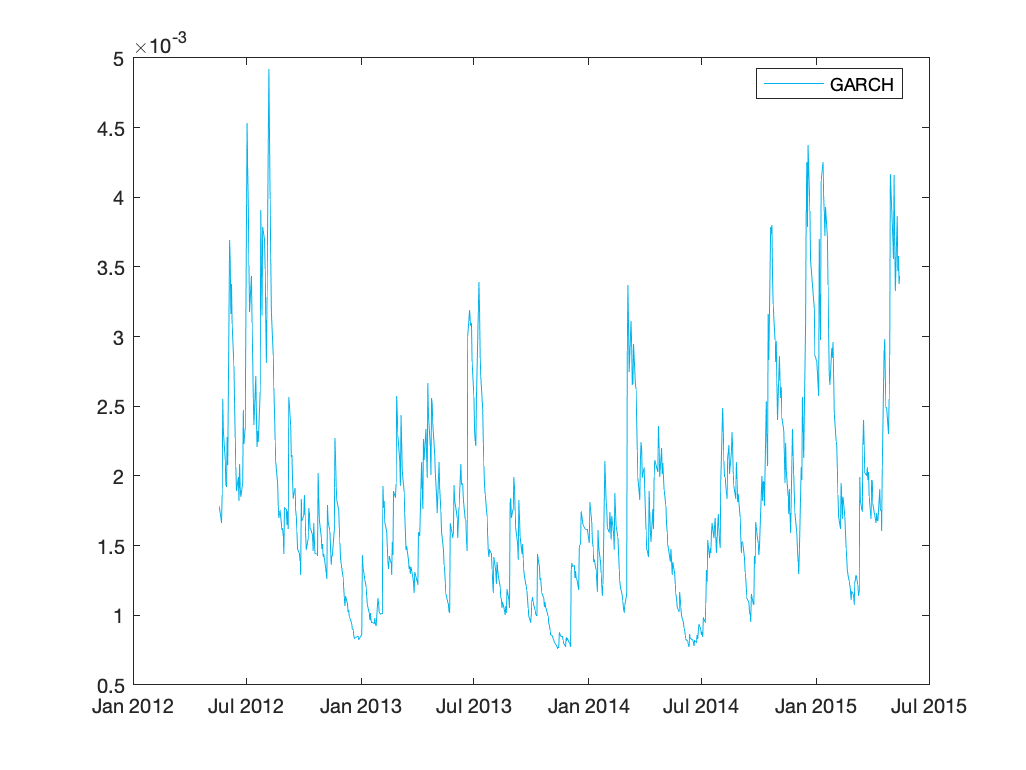

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");

Timeline_insample=datatable.Date(index);

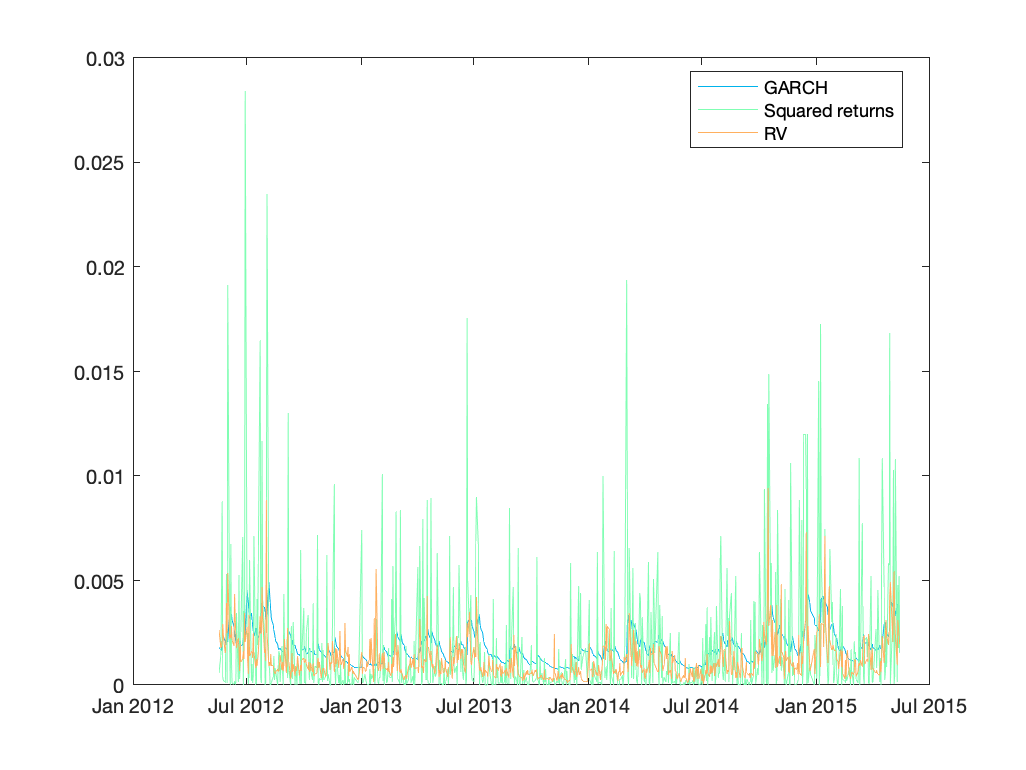

figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(3,:))
legend("GARCH","Squared returns","RV","Location","best");

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
subplot(2,2,1)
plot(Timeline_insample,v_GARCH, "Color",col(1,:))
legend("GARCH","Location","best");
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 8.6298e-04

subplot(2,2,2)
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
legend("GJR","Location","best");
mse(v_GJRGARCH,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_GJRGARCH-rv))*sqrt(250)

ans = 8.4449e-04

subplot(2,2,3)
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
legend("RSGARCH","Location","best");
mse(v_RSGARCH,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_RSGARCH-rv))*sqrt(250)

ans = 8.7753e-04

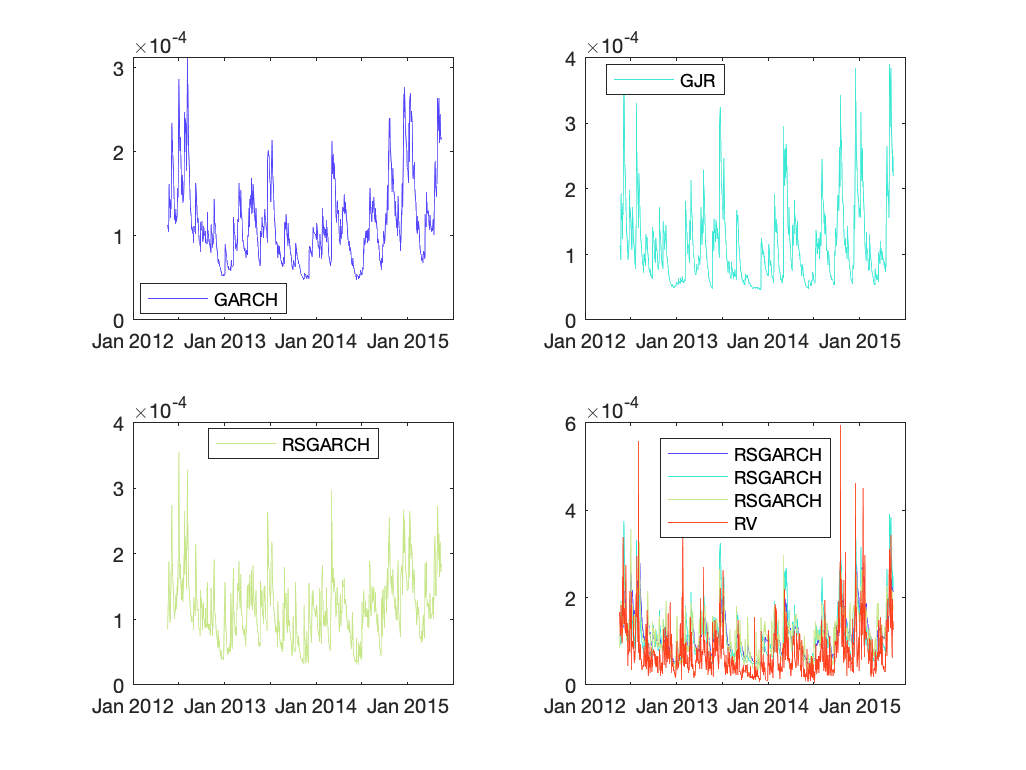

subplot(2,2,4)
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
plot(Timeline_insample,rv, "Color",col(10,:));
legend("RSGARCH","RSGARCH","RSGARCH","RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_GARCH_GJR_RSGARCH.png'])

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 8.6298e-04

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
% K = OptimalClusterNumber(v_GARCH,LB);
K = 2;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH1,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_CPGARCH1-rv))*sqrt(250)

ans = 9.4870e-04

K = 3;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH2,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_CPGARCH2-rv))*sqrt(250)

ans = 9.1878e-04

K = 4;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH3,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_CPGARCH3-rv))*sqrt(250)

ans = 9.1571e-04

K = 5;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH4,rv).^(1/2)*sqrt(250)

ans = 0.0011

mean(abs(v_CPGARCH4-rv))*sqrt(250)

ans = 9.1847e-04

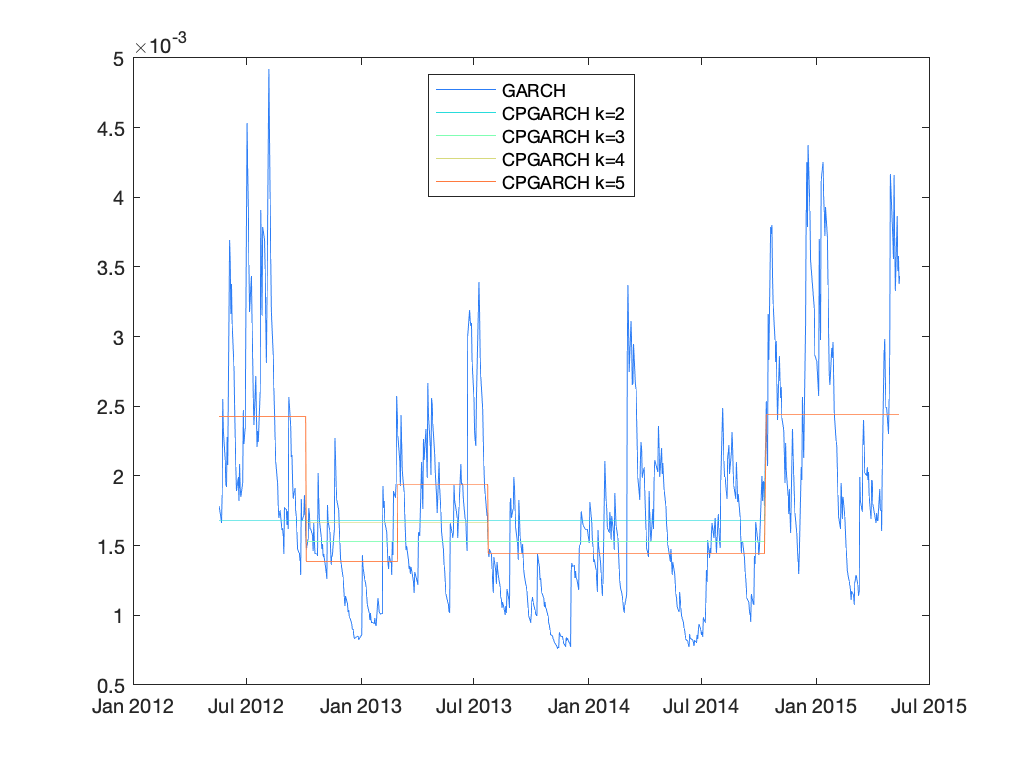

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","Location","best");

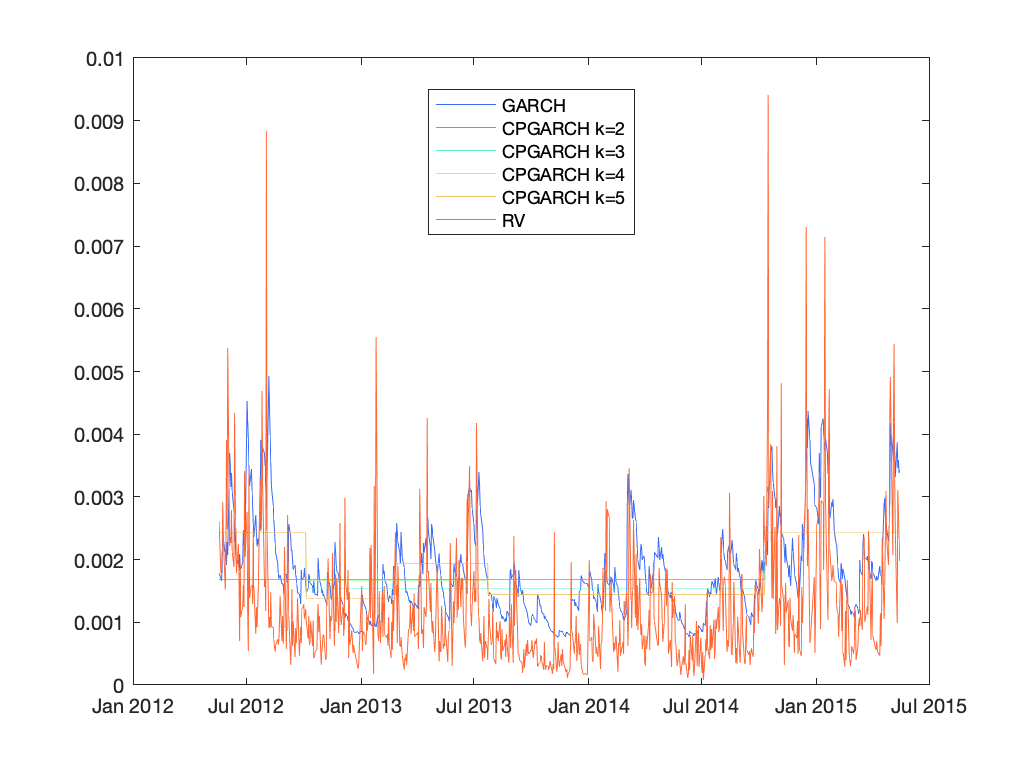

figure;
col=rainbow(6);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(6,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","RV","Location","best");

% RMSE=zeros(size(2:300));
% MAE=zeros(size(2:300));
% K_h=zeros(size(2:300));
% for h=2:300
%     h
%     [LB,J,~]=Fisher_div_sqr(v_GARCH,h);
%     K = OptimalClusterNumber(v_GARCH,LB);
%     v_CPGARCH=Vol_ClusterPartition(v_GARCH,K,J);
%     K_h(h-1)=K;
%     RMSE(h-1)=mse(v_CPGARCH,rv).^(1/2)*sqrt(250);
%     MAE(h-1)=mean(abs(v_CPGARCH-rv))*sqrt(250);
% end
% figure;
% plot(2:300,K_h)
% figure;
% subplot(2,1,1);
% plot(RMSE);
% legend("rmse","Location","best");
% subplot(2,1,2);
% plot(MAE);
% legend("mae","Location","best");

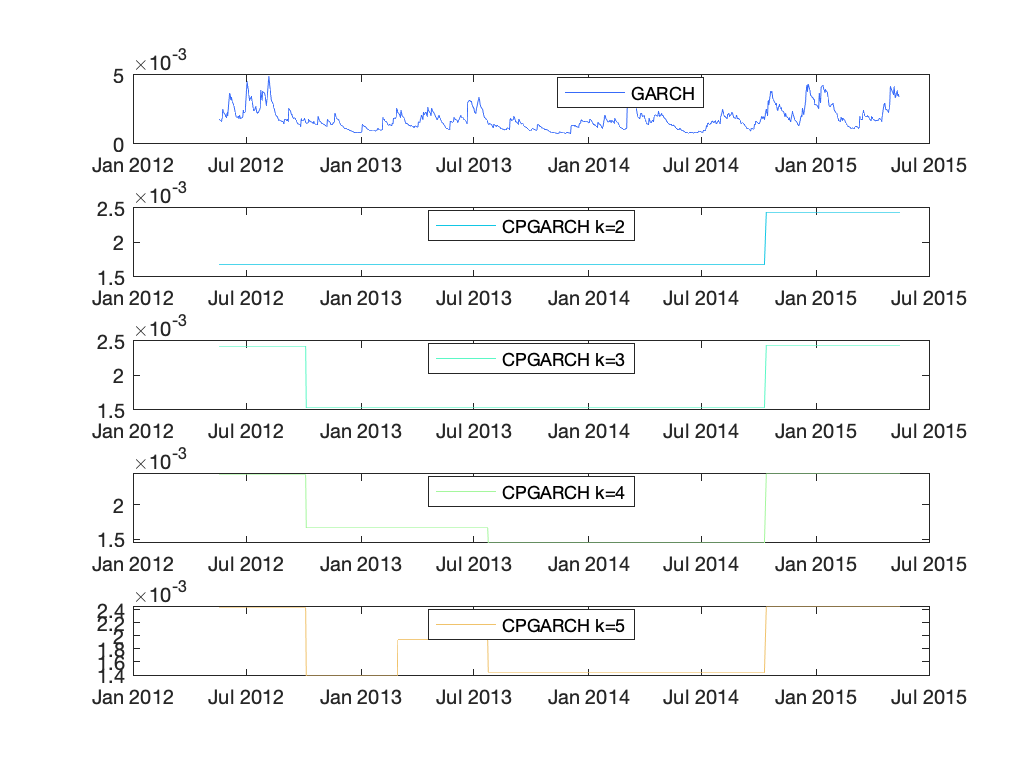

figure;
subplot(5,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");
subplot(5,1,2);
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
legend("CPGARCH k=2","Location","best");
subplot(5,1,3);
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
legend("CPGARCH k=3","Location","best");
subplot(5,1,4);
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
legend("CPGARCH k=4","Location","best");
subplot(5,1,5);
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("CPGARCH k=5","Location","best");

ret=datatable.Return(index);
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,10);
K = OptimalClusterNumber(v_GARCH,LB)

K = 44

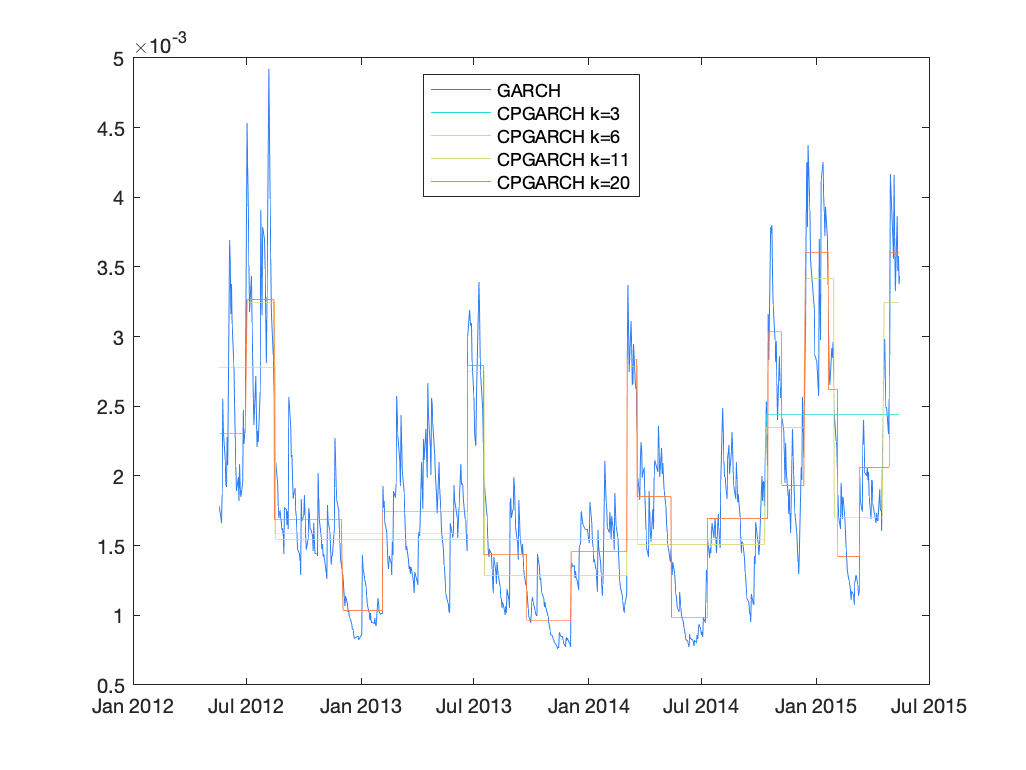

K = 3;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 6;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 11;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 20;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=3","CPGARCH k=6","CPGARCH k=11","CPGARCH k=20","Location","best");

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 7

[v_CPGARCH,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   101
   201
   301
   405
   505
   610


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K2 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K2 = 3

[v_CPsr,Nodes2]=Vol_ClusterPartition(datatable.Return(index).^2,K2,J);
Nodes2

Nodes2 =      1
   103
   604


[LB,J,~]=Fisher_div_sqr(rv,100);
K3 = OptimalClusterNumber(rv,LB)

K3 = 5

[v_CPrv,Nodes3]=Vol_ClusterPartition(rv,K3,J);
Nodes3

Nodes3 =      1
   101
   291
   427
   604


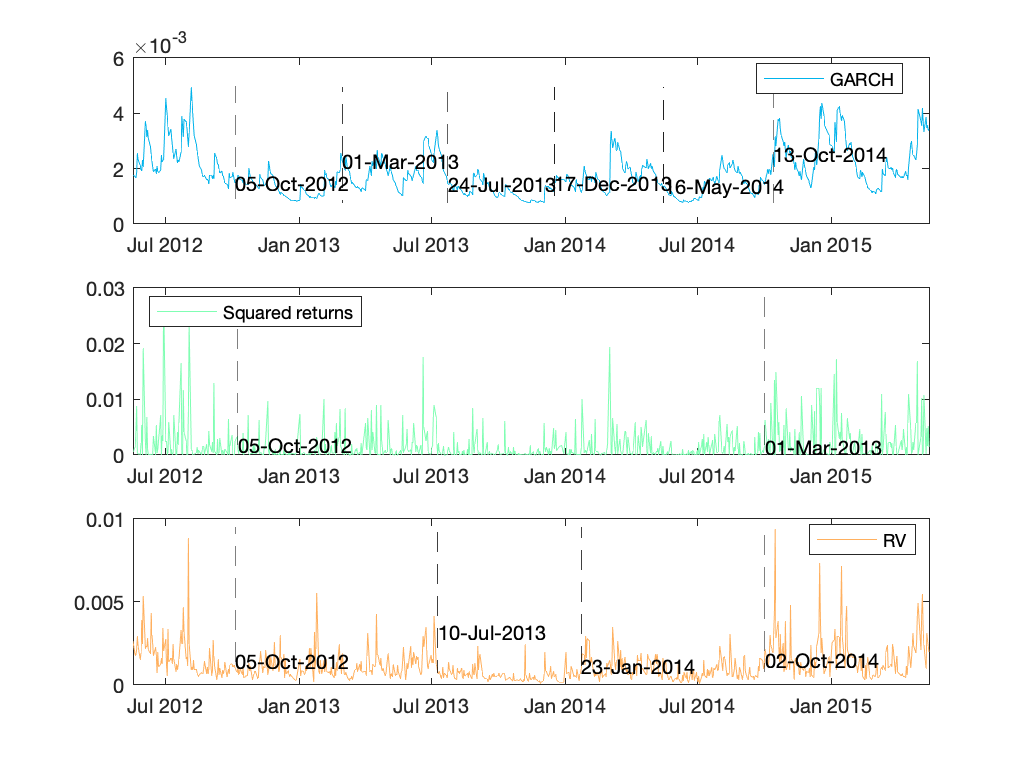

figure;
col=rainbow(3);
subplot(3,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes1)
plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes1(i)),v_GARCH(Nodes1(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
% plot([Timeline_insample(Nodes1(3)),Timeline_insample(Nodes1(3))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
% text(Timeline_insample(Nodes1(3)),v_GARCH(Nodes1(2))*sqrt(250),datestr(Timeline_insample(Nodes1(3))))
legend("GARCH","Location","best");
subplot(3,1,2);
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250), "Color",col(2,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes2)
plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[min(datatable.Return(index).^2*sqrt(250))*0.99,max(datatable.Return(index).^2*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes2(i)),v_GARCH(Nodes2(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
legend("Squared returns","Location","northwest");
subplot(3,1,3);
plot(Timeline_insample,rv*sqrt(250), "Color",col(3,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes3)
plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[min(v_GARCH*sqrt(250))*0.99,max(rv*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes3(i)),v_GARCH(Nodes3(i))*sqrt(250),datestr(Timeline_insample(Nodes3(i))))
end
legend("RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_CP.png'])

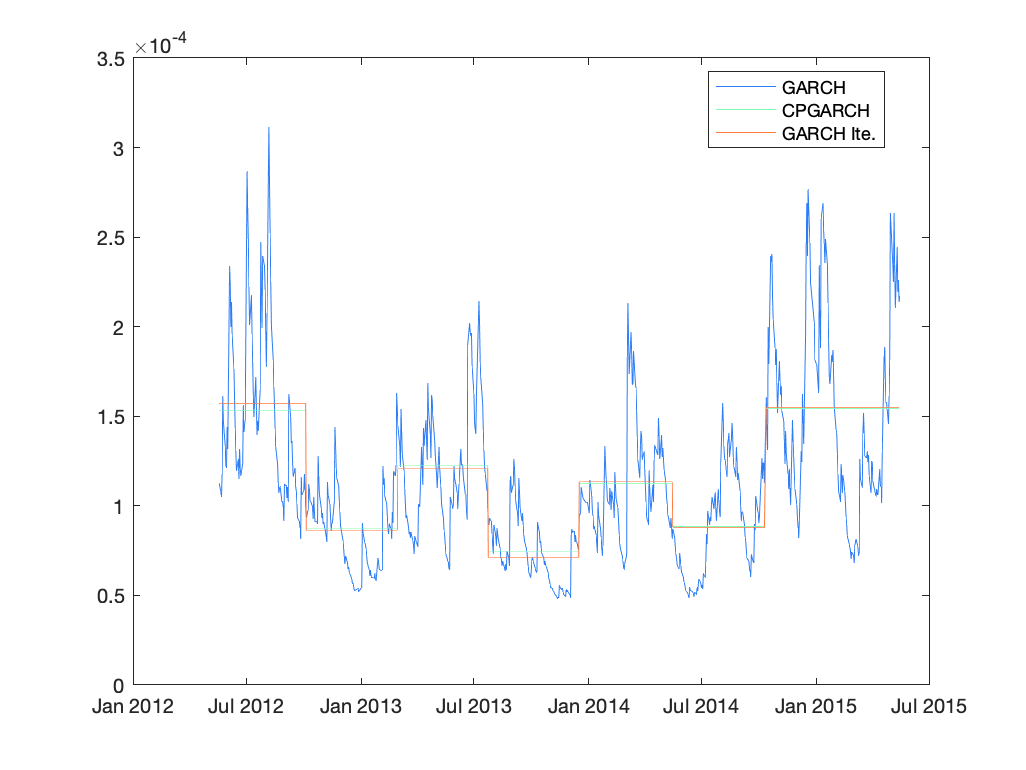

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH, "Color",col(3,:))
plot(Timeline_insample,v_CPGARCHiteration, "Color",col(5,:))
legend("GARCH","CPGARCH","GARCH Ite.","Location","best");

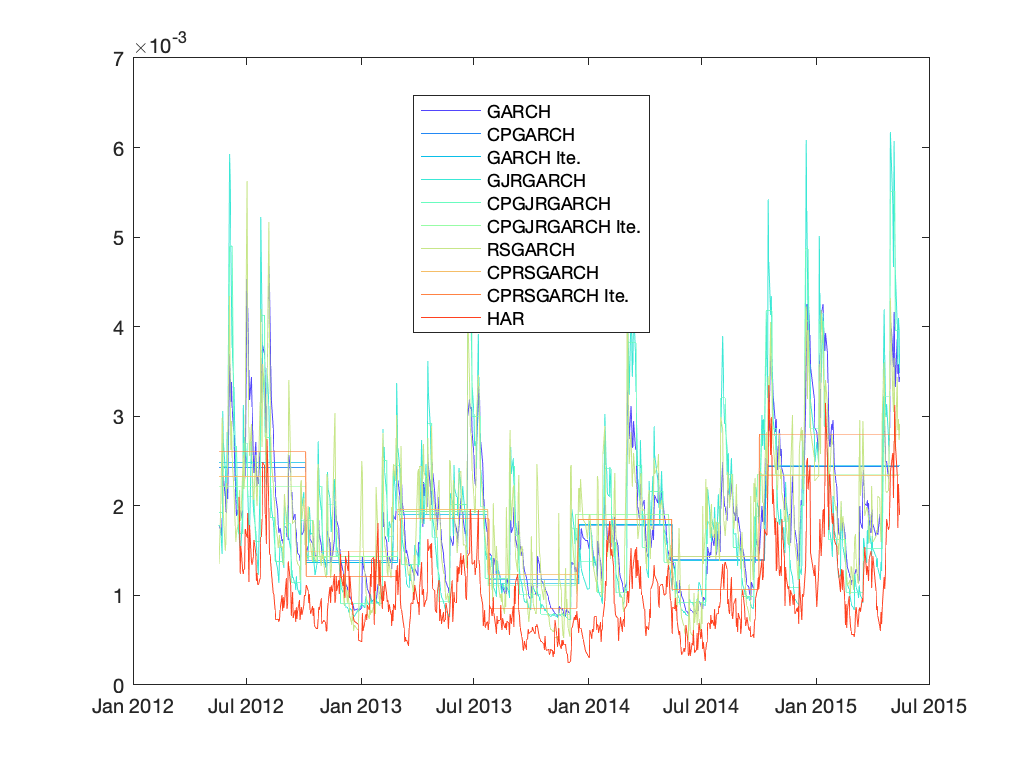

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(7,:));
plot(Timeline_insample,v_CPRSGARCH*sqrt(250), "Color",col(8,:))
plot(Timeline_insample,v_CPRSGARCHiteration*sqrt(250), "Color",col(9,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(10,:))
%plot(Time_insample,v_RSGARCH, "Color",col(10,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","Location","best");

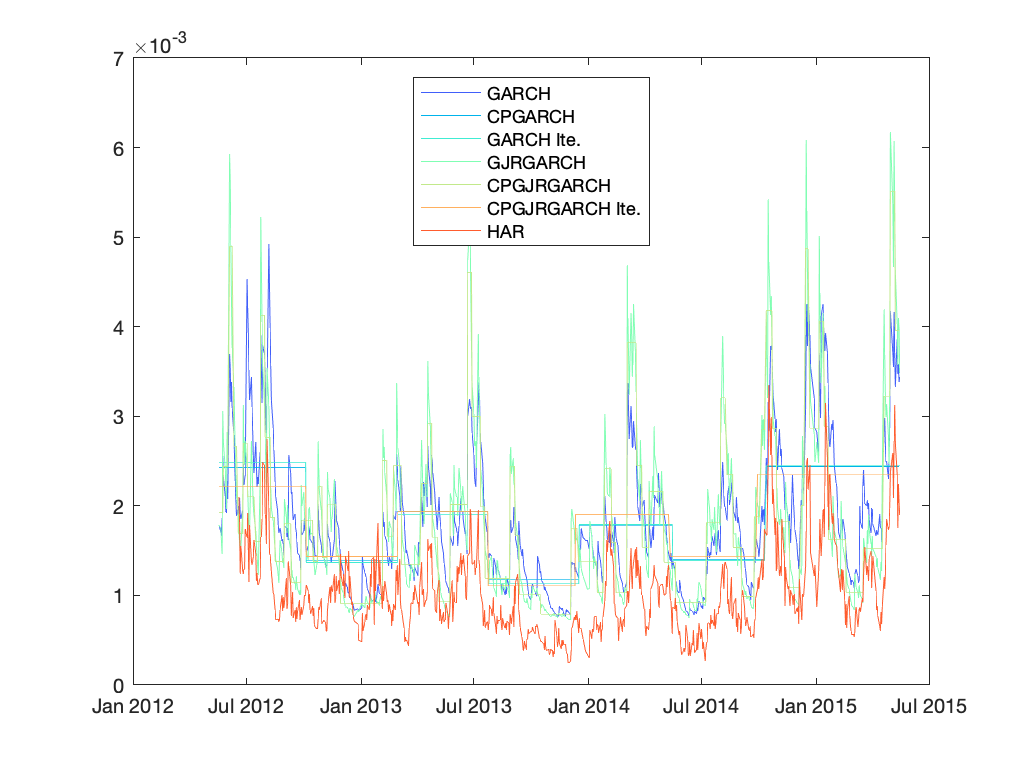

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(7);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(7,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH","CPGJRGARCH","CPGJRGARCH Ite.","HAR","Location","best");

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.86298     1.0937
    CPGARCH            0.90894     1.1169
    GARCH Ite.         0.90539     1.1173
    GJRGARCH           0.84449     1.1135
    CPGJRGARCH         0.84717     1.1054
    CPGJRGARCH Ite.    0.90191     1.1065
    RSGARCH            0.87753      1.113
    CPRSGARCH          0.91854     1.1179
    CPRSGARCH Ite.      0.8971     1.1478
    HAR                0.49551    0.83886
    HAR_a              0.48039    0.81502
    CPHAR              0.48354    0.81824
    CPHAR_a            0.46019    0.78382


## FTSE 100

datatable=readtable("FTSE_0608.xlsx");
results_folder='Results_FTSE';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);
% symmetric HAR
lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -1.6601     0.42377    -3.9176    9.7848e-05
    x1              0.28158    0.044315     6.3539    3.6936e-10
    x2              0.47992    0.070065     6.8496    1.5736e-11
    x3             0.079609    0.063045     1.2627       0.20709


Number of observations: 734, Error degrees of freedom: 730
Root Mean Squared Error: 0.457
R-squared: 0.456,  Adjusted R-Squared: 0.454
F-statistic vs. constant model: 204, p-value = 4.37e-96

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 1.2868e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 2.2276e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 1.2536e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 2.1634e-05


% asymmetric HAR
lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      -1.6301     0.41864     -3.8938    0.00010775
    x1                0.1942    0.046818       4.148    3.7503e-05
    x2                0.5502    0.070742      7.7774    2.5373e-14
    x3               0.10335    0.062244      1.6603      0.097278
    x4               -1841.5      1728.8     -1.0651       0.28716
    x5             -0.020075    0.023899    -0.83996       0.40121
    x6               0.15095    0.029157      5.1771    2.9198e-07


Number of observations: 734, Error degrees o

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 1.2590e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 2.1791e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 1.2188e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 2.0677e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    true      0.01     7.77     6.63 
    true      0.01     7.77     3.84 
    true      0.01     7.77     2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    5.0693e-06     1.6426e-06        3.0861        0.0020281
    GARCH{1}       0.79555       0.032972        24.128      1.2792e-128
    ARCH{1}        0.12391       0.025901        4.7839       1.7189e-06
    Offset      0.00047902      0.0002433        1.9688         0.048973



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
% if K==numel(v_GARCH)
%     K=K-1;
% end
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

EGARCH

% Mdl=egarch('GARCH',NaN,'ARCH',NaN,'Offset',NaN,'Leverage',NaN);
% EstMdl = estimate(Mdl,ret);
% v_EGARCH = infer(EstMdl,ret);
% [LB,J,~]=Fisher_div_sqr(v_EGARCH,100);
% K = OptimalClusterNumber(v_EGARCH,LB);
% % if K==numel(v_EGARCH)
% %     K=K-1;
% % end
% [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
% v_CPEGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPEGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
                   __________    _____________    __________    ___________

    Constant       4.7657e-06     1.2712e-06          3.7491     0.00017751
    GARCH{1}          0.79724       0.026109          30.535    9.0519e-205
    ARCH{1}             2e-12        0.02455      8.1467e-11              1
    Leverage{1}       0.25836       0.046134          5.6002     2.1415e-08
    Offset         0.00017673     0.00025383         0.69626        0.48627



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
% if K==numel(v_GJRGARCH)
%     K=K-1;
% end
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation, probabilities, ~] = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0000    0.1361    0.4906
    0.0000    0.3544    0.6501


estimation.transM

ans =     0.6958    0.4272
    0.3042    0.5728


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
% if K==numel(v_RSGARCH)
%     K=K-1;
% end
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 3.4539e-05

mean(abs(v_CPRSGARCH-rv))

ans = 3.5503e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 3.0192e-05

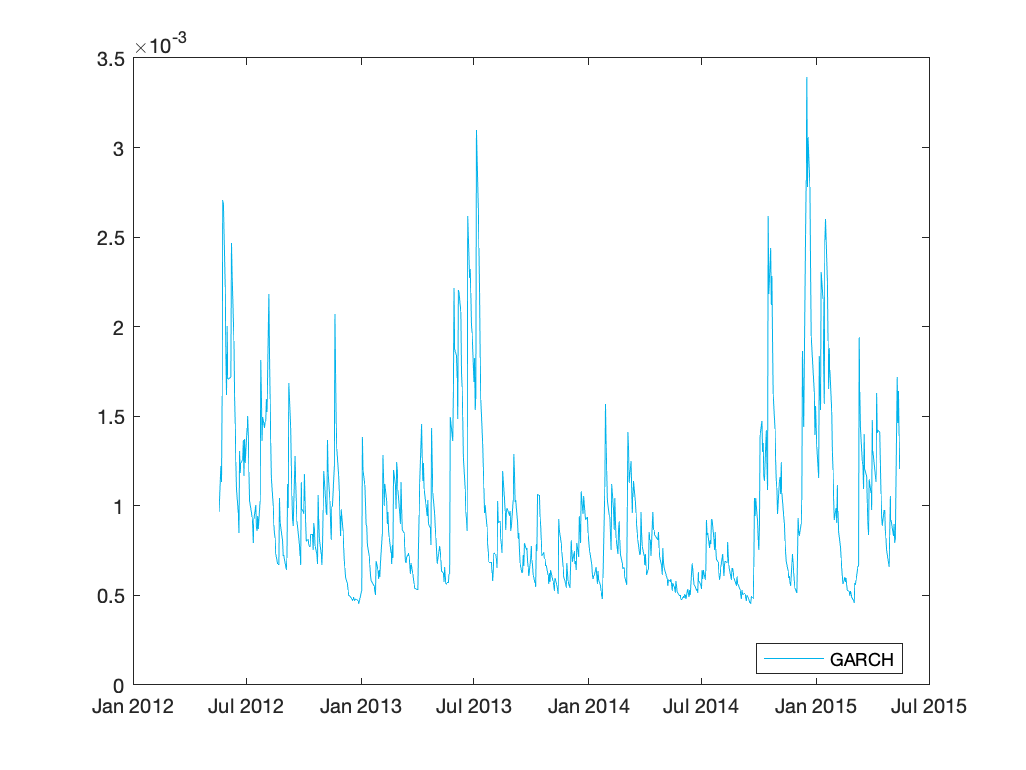

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");

Timeline_insample=datatable.Date(index);

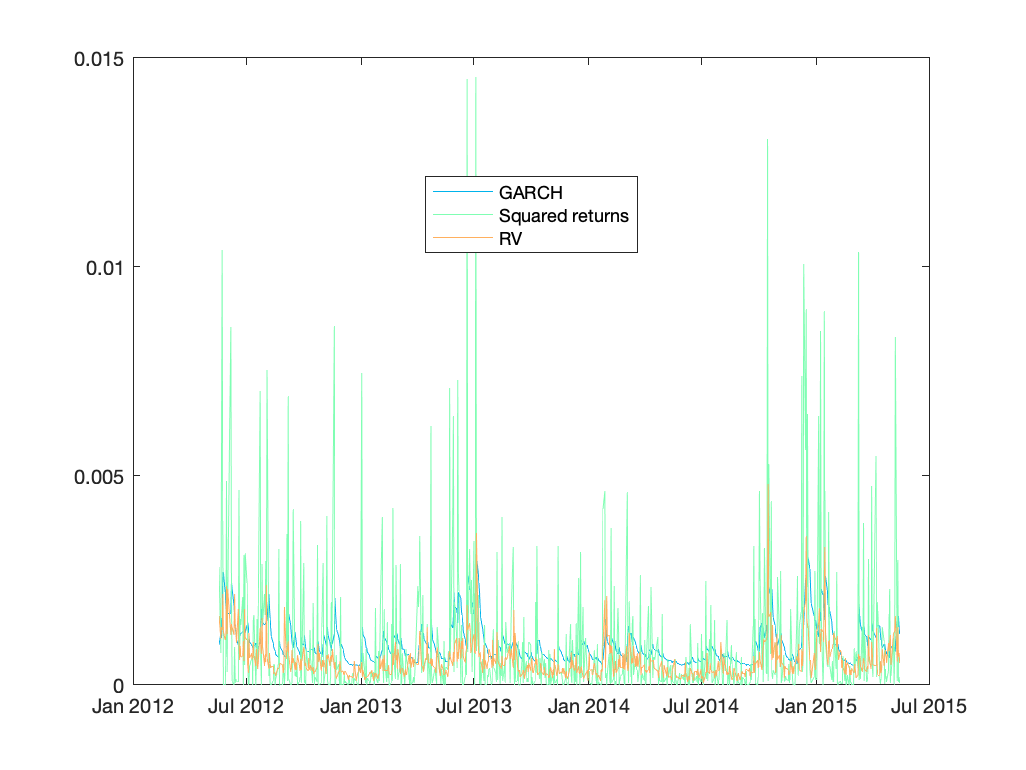

figure;
col=rainbow(3);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(3,:))
legend("GARCH","Squared returns","RV","Location","best");

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
subplot(2,2,1)
plot(Timeline_insample,v_GARCH, "Color",col(1,:))
legend("GARCH","Location","best");
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 5.7442e-04

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 4.5916e-04

subplot(2,2,2)
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
legend("GJR","Location","best");
mse(v_GJRGARCH,rv).^(1/2)*sqrt(250)

ans = 6.8572e-04

mean(abs(v_GJRGARCH-rv))*sqrt(250)

ans = 4.8048e-04

subplot(2,2,3)
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
legend("RSGARCH","Location","best");
mse(v_RSGARCH,rv).^(1/2)*sqrt(250)

ans = 7.3010e-04

mean(abs(v_RSGARCH-rv))*sqrt(250)

ans = 5.4610e-04

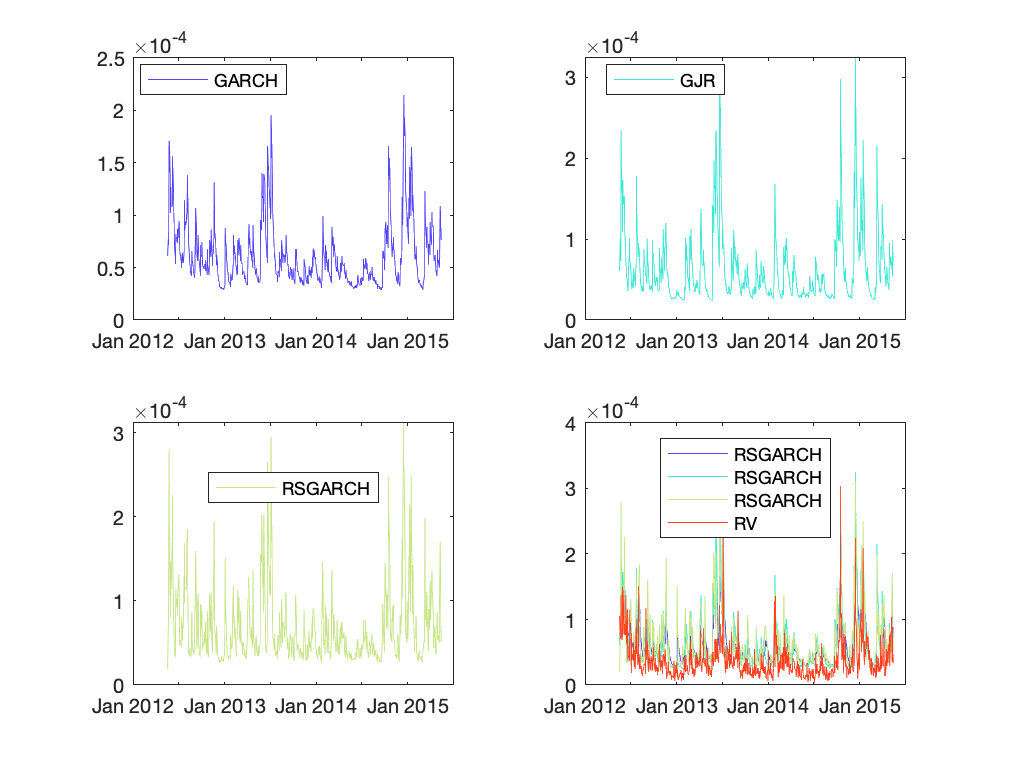

subplot(2,2,4)
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_GJRGARCH, "Color",col(4,:));
plot(Timeline_insample,v_RSGARCH, "Color",col(7,:));
plot(Timeline_insample,rv, "Color",col(10,:));
legend("RSGARCH","RSGARCH","RSGARCH","RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_GARCH_GJR_RSGARCH.png'])

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
mse(v_GARCH,rv).^(1/2)*sqrt(250)

ans = 5.7442e-04

mean(abs(v_GARCH-rv))*sqrt(250)

ans = 4.5916e-04

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
% K = OptimalClusterNumber(v_GARCH,LB);
K = 2;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH1,rv).^(1/2)*sqrt(250)

ans = 5.8733e-04

mean(abs(v_CPGARCH1-rv))*sqrt(250)

ans = 5.0748e-04

K = 3;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH2,rv).^(1/2)*sqrt(250)

ans = 5.8395e-04

mean(abs(v_CPGARCH2-rv))*sqrt(250)

ans = 4.9599e-04

K = 4;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH3,rv).^(1/2)*sqrt(250)

ans = 5.7313e-04

mean(abs(v_CPGARCH3-rv))*sqrt(250)

ans = 4.8740e-04

K = 5;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
mse(v_CPGARCH4,rv).^(1/2)*sqrt(250)

ans = 5.6656e-04

mean(abs(v_CPGARCH4-rv))*sqrt(250)

ans = 4.8098e-04

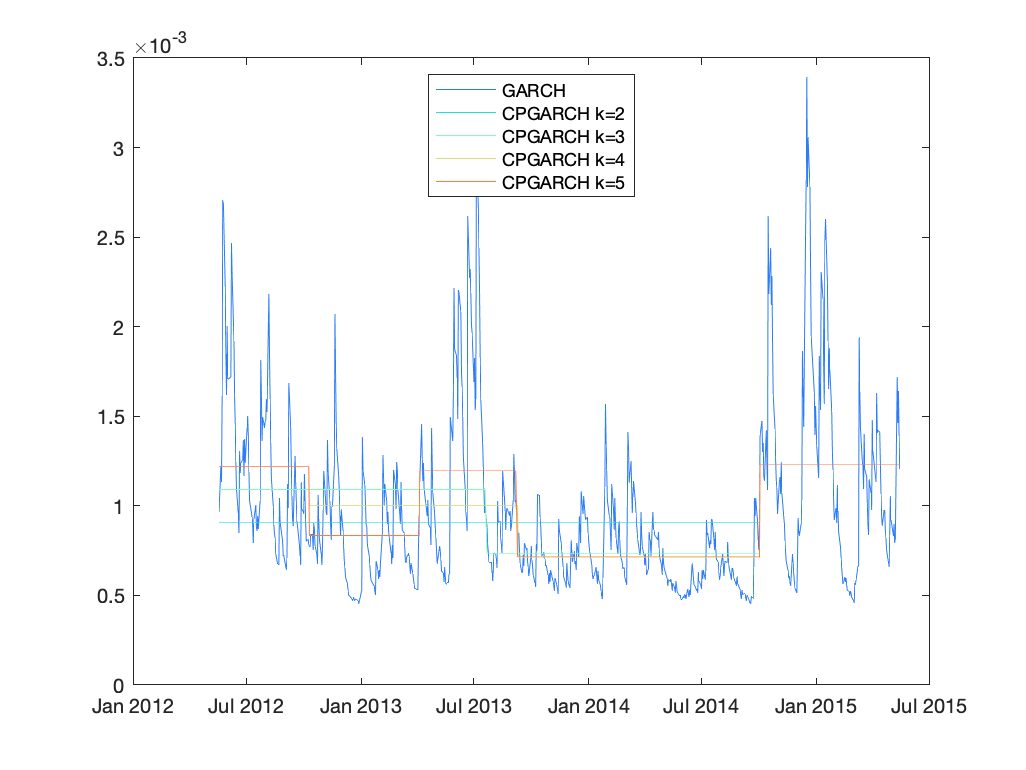

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","Location","best");

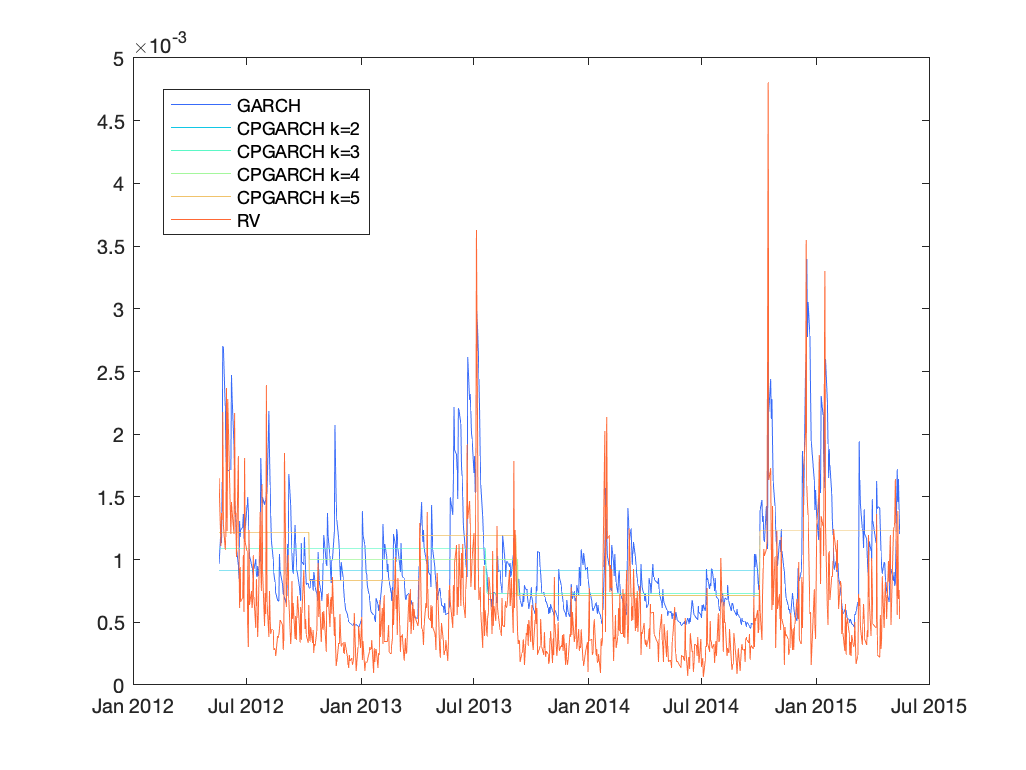

figure;
col=rainbow(6);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
plot(Timeline_insample,rv*sqrt(250),"Color",col(6,:))
legend("GARCH","CPGARCH k=2","CPGARCH k=3","CPGARCH k=4","CPGARCH k=5","RV","Location","best");

% RMSE=zeros(size(2:300));
% MAE=zeros(size(2:300));
% K_h=zeros(size(2:300));
% for h=2:300
%     h
%     [LB,J,~]=Fisher_div_sqr(v_GARCH,h);
%     K = OptimalClusterNumber(v_GARCH,LB);
%     v_CPGARCH=Vol_ClusterPartition(v_GARCH,K,J);
%     K_h(h-1)=K;
%     RMSE(h-1)=mse(v_CPGARCH,rv).^(1/2)*sqrt(250);
%     MAE(h-1)=mean(abs(v_CPGARCH-rv))*sqrt(250);
% end
% figure;
% plot(2:300,K_h)
% figure;
% subplot(2,1,1);
% plot(RMSE);
% legend("rmse","Location","best");
% subplot(2,1,2);
% plot(MAE);
% legend("mae","Location","best");

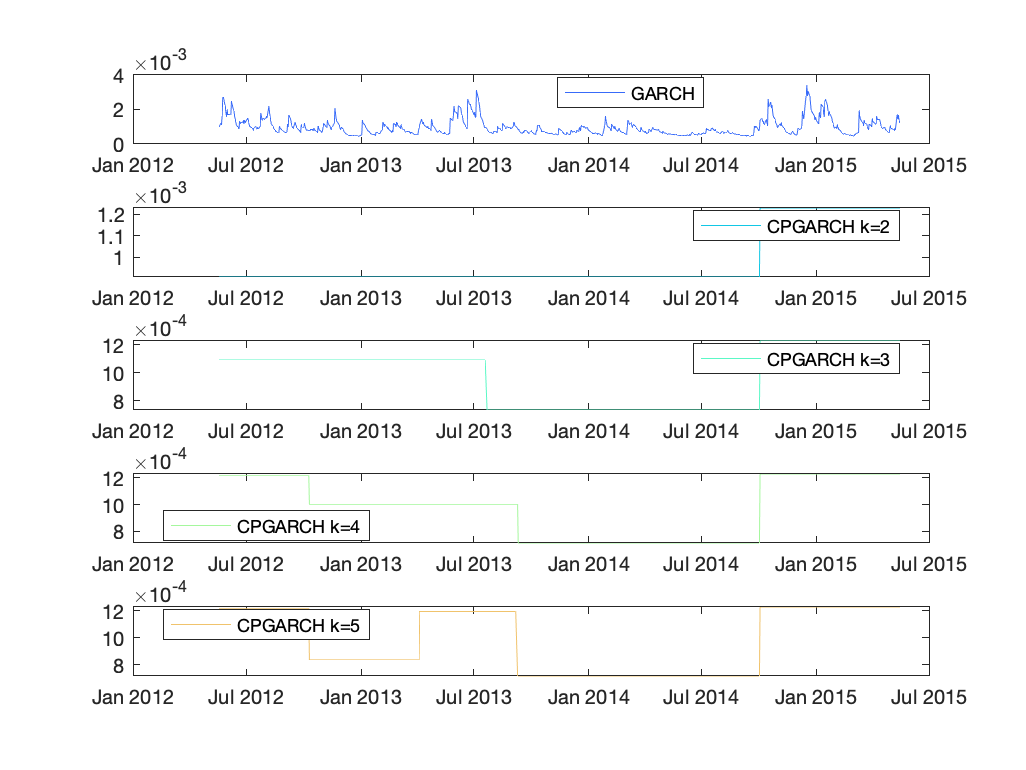

figure;
subplot(5,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
legend("GARCH","Location","best");
subplot(5,1,2);
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
legend("CPGARCH k=2","Location","best");
subplot(5,1,3);
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
legend("CPGARCH k=3","Location","best");
subplot(5,1,4);
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
legend("CPGARCH k=4","Location","best");
subplot(5,1,5);
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("CPGARCH k=5","Location","best");

ret=datatable.Return(index);
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret,'Display','off');
v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,10);
K = OptimalClusterNumber(v_GARCH,LB)

K = 40

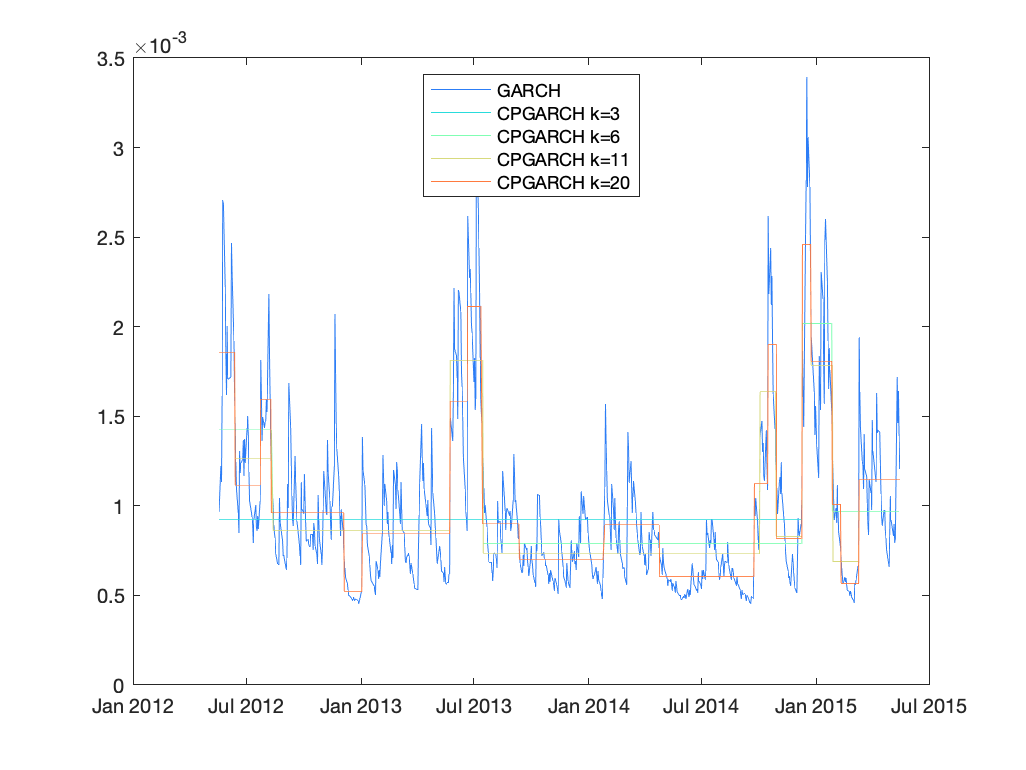

K = 3;
[v_CPGARCH1,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 6;
[v_CPGARCH2,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 11;
[v_CPGARCH3,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
K = 20;
[v_CPGARCH4,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH1*sqrt(250),"Color",col(2,:))
plot(Timeline_insample,v_CPGARCH2*sqrt(250),"Color",col(3,:))
plot(Timeline_insample,v_CPGARCH3*sqrt(250),"Color",col(4,:))
plot(Timeline_insample,v_CPGARCH4*sqrt(250),"Color",col(5,:))
legend("GARCH","CPGARCH k=3","CPGARCH k=6","CPGARCH k=11","CPGARCH k=20","Location","best");

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 6

[v_CPGARCH,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   101
   223
   331
   491
   602


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K2 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K2 = 3

[v_CPsr,Nodes2]=Vol_ClusterPartition(datatable.Return(index).^2,K2,J);
Nodes2

Nodes2 =      1
   289
   593


[LB,J,~]=Fisher_div_sqr(rv,100);
K3 = OptimalClusterNumber(rv,LB)

K3 = 6

[v_CPrv,Nodes3]=Vol_ClusterPartition(rv,K3,J);
Nodes3

Nodes3 =      1
   101
   211
   331
   487
   601


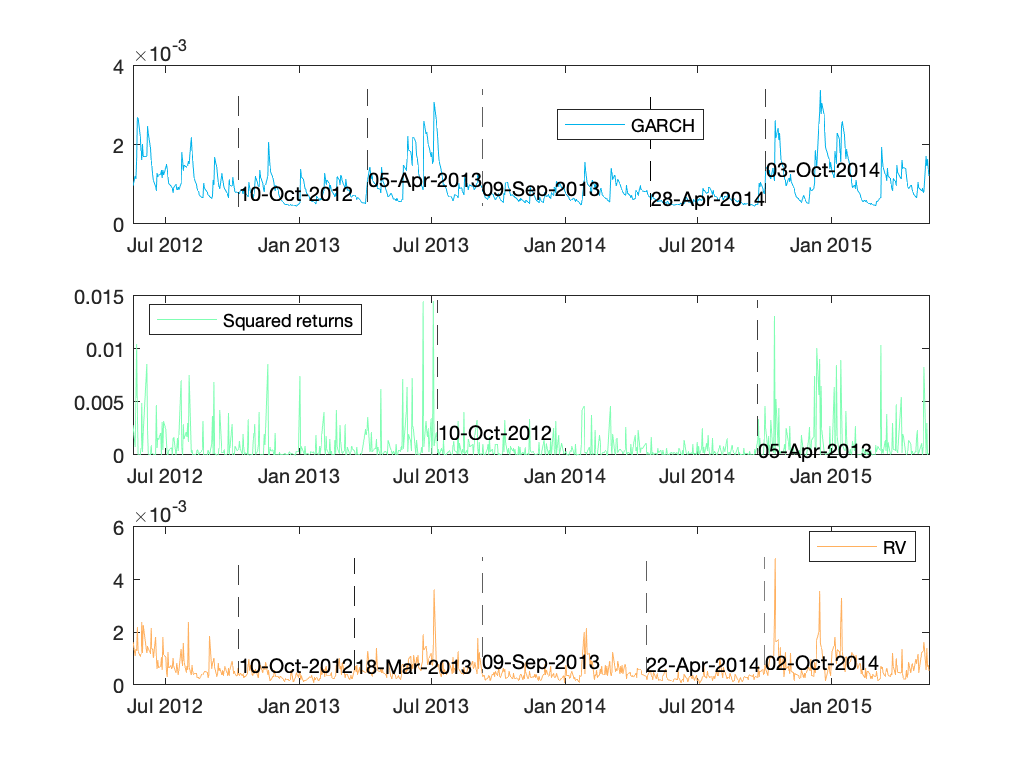

figure;
col=rainbow(3);
subplot(3,1,1);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes1)
plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes1(i)),v_GARCH(Nodes1(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
% plot([Timeline_insample(Nodes1(3)),Timeline_insample(Nodes1(3))],[min(v_GARCH*sqrt(250))*0.99,max(v_GARCH*sqrt(250))*1.01],'k--')
% text(Timeline_insample(Nodes1(3)),v_GARCH(Nodes1(2))*sqrt(250),datestr(Timeline_insample(Nodes1(3))))
legend("GARCH","Location","best");
subplot(3,1,2);
plot(Timeline_insample,datatable.Return(index).^2*sqrt(250), "Color",col(2,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes2)
plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[min(datatable.Return(index).^2*sqrt(250))*0.99,max(datatable.Return(index).^2*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes2(i)),v_GARCH(Nodes2(i))*sqrt(250),datestr(Timeline_insample(Nodes1(i))))
end
legend("Squared returns","Location","northwest");
subplot(3,1,3);
plot(Timeline_insample,rv*sqrt(250), "Color",col(3,:));
xlim([Timeline_insample(1),Timeline_insample(end)])
% xlabel('Year')
% ylabel('\sigma')
% dateaxis('x' , 12)
hold on
for i=2:length(Nodes3)
plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[min(v_GARCH*sqrt(250))*0.99,max(rv*sqrt(250))*1.01],'k--')
text(Timeline_insample(Nodes3(i)),v_GARCH(Nodes3(i))*sqrt(250),datestr(Timeline_insample(Nodes3(i))))
end
legend("RV","Location","best");
saveas(gcf,[results_folder,'/Volatility_CP.png'])

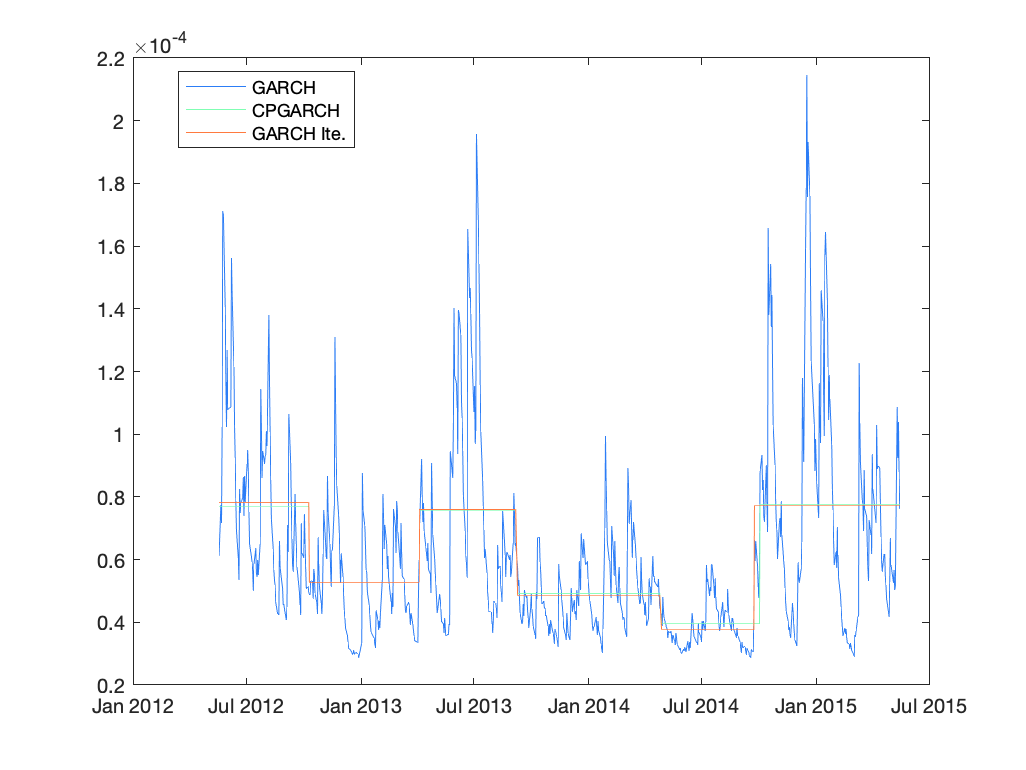

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(5);
plot(Timeline_insample,v_GARCH, "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH, "Color",col(3,:))
plot(Timeline_insample,v_CPGARCHiteration, "Color",col(5,:))
legend("GARCH","CPGARCH","GARCH Ite.","Location","best");

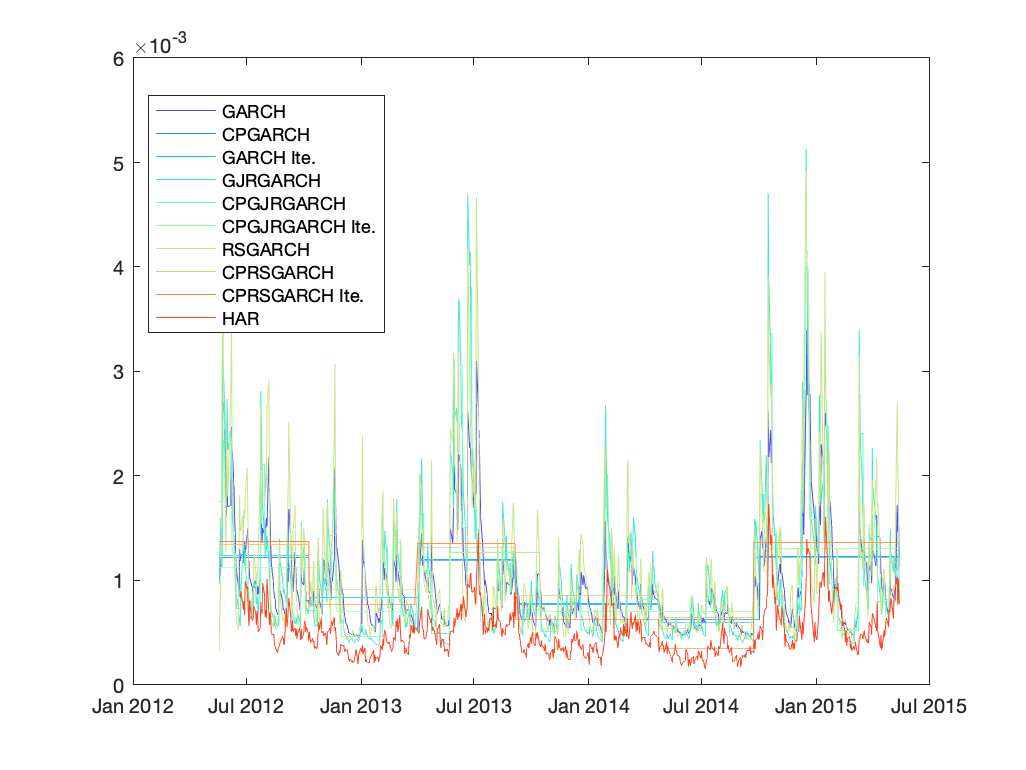

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(10);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(7,:));
plot(Timeline_insample,v_CPRSGARCH*sqrt(250), "Color",col(8,:))
plot(Timeline_insample,v_CPRSGARCHiteration*sqrt(250), "Color",col(9,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(10,:))
%plot(Time_insample,v_RSGARCH, "Color",col(10,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","Location","best");

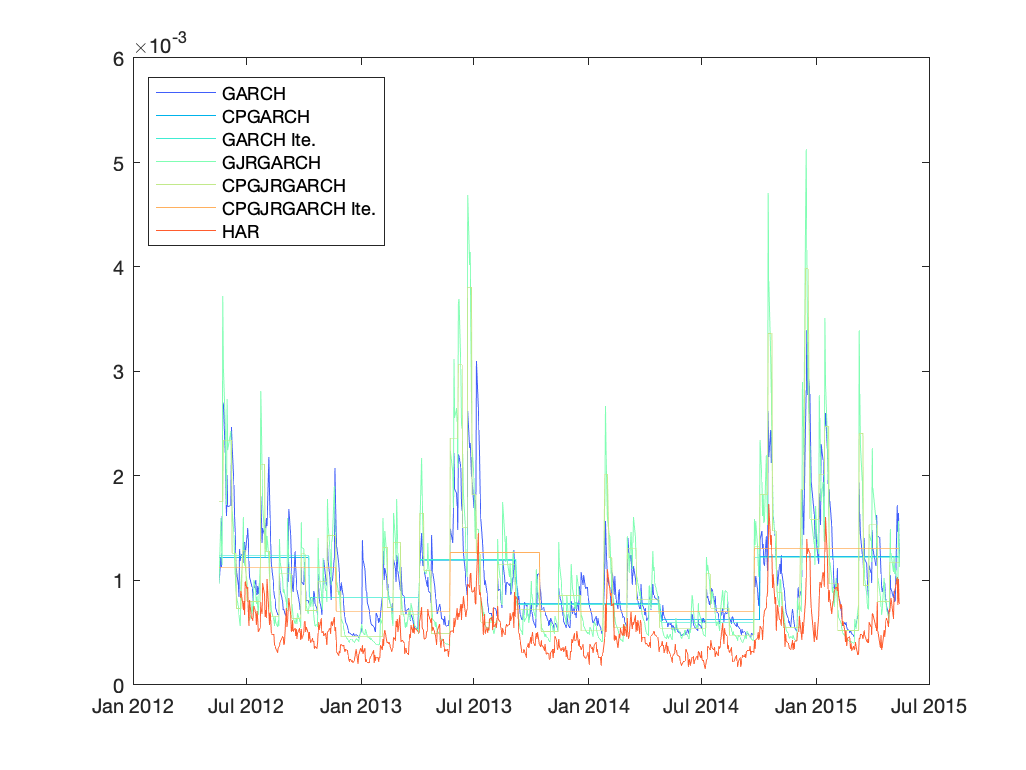

Timeline_insample=datatable.Date(index);
figure;
col=rainbow(7);
plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));hold on
plot(Timeline_insample,v_CPGARCH*sqrt(250), "Color",col(2,:))
plot(Timeline_insample,v_CPGARCHiteration*sqrt(250), "Color",col(3,:))
plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(4,:));
plot(Timeline_insample,v_CPGJRGARCH*sqrt(250), "Color",col(5,:))
plot(Timeline_insample,v_CPGJRGARCHiteration*sqrt(250), "Color",col(6,:))
plot(Timeline_insample(23:end),v_HAR*sqrt(250), "Color",col(7,:))
legend("GARCH","CPGARCH","GARCH Ite.", ...
    "GJRGARCH","CPGJRGARCH","CPGJRGARCH Ite.","HAR","Location","best");

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.45916    0.57442
    CPGARCH            0.47903    0.56503
    GARCH Ite.         0.48047    0.56746
    GJRGARCH           0.48048    0.68572
    CPGJRGARCH         0.47156     0.6638
    CPGJRGARCH Ite.    0.49107    0.58219
    RSGARCH             0.5461     0.7301
    CPRSGARCH          0.56136    0.64258
    CPRSGARCH Ite.     0.47737    0.59933
    HAR                0.20346    0.35221
    HAR_a              0.19906    0.34454
    CPHAR              0.19822    0.34206
    CPHAR_a            0.19271    0.32694


Summary statistics

sp=readtable("SP500_0608.xlsx");
dax=readtable("DAX_0608.xlsx");
ftse=readtable("FTSE_0608.xlsx");
Mean=[mean(sp.Return);mean(dax.Return);mean(ftse.Return)];
STD=[std(sp.Return);std(dax.Return);std(ftse.Return)];